## Advanced E/I Neuron Classification and Neurophysiological Analysis

for each cluster, make the cross/autocorrelelogram, plot the spike width, asymmetry index.

Author: Coby Bowman

Date: September 15, 2025

Dataset: Steinmetz et al., 2019 (VISp region)

Objective: This script performs a multi-stage analysis of neuronal data. It begins with a sophisticated classification of neurons into excitatory (E) and inhibitory (I) types, validates the classification, analyzes the suitability of this method across different cortical layers, and concludes with an analysis of the neurons' temporal dynamics and functional connectivity.

## 1. Data Loading & Preprocessing

First, we load the necessary metadata and raw data, including channel locations, spike times, cluster assignments, and template waveforms. The primary goal is to isolate data from the **primary visual cortex (VISp)** for analysis.

## 2. Enhanced E/I Classification Pipeline

This pipeline uses a robust, **multi-feature clustering approach** to discover natural E/I groupings in the data, avoiding the limitations of single-feature thresholding.

**2.1. Feature Extraction**

We extract two informative features from each neuron's average waveform:

- **Spike Width**: The full-width at half-minimum of the trough.

- **Peak-to-Trough Ratio**: The ratio of the repolarization peak to the hyperpolarization trough.

**2.2. K-Means Clustering for Classification**

We use the **k-means clustering algorithm** to find the two most distinct groups in the 2D feature space. This is a more objective method than manually setting a threshold, especially for unimodal distributions. The cluster with the narrower average spike width is assigned the "putative inhibitory" label.

**2.3. Classification Visualization**

The results are visualized with two plots:

- **Scatter Plot**: Shows the two discovered clusters and their centers (centroids) in the 2D feature space.

- **Histogram**: Shows the spike width distributions for the two classes as determined by k-means.

## 3. Layer-Aware Bimodality Analysis

This section investigates *where* spike-width-based E/I classification is most effective by stratifying the analysis by cortical layer.

**3.1. Layer Assignment**

Neurons are grouped into putative cortical layers (e.g., L2/3, L4, L5, L6) based on the recording depth of their peak channel.

**3.2. Per-Layer Distribution Testing**

For each layer, we create spike width histograms and test if the distribution is unimodal (one group) or bimodal (two distinct E/I groups) using multiple statistical methods:

- **Hartigan's Dip Test**: A statistical test for multimodality. A low p-value suggests the presence of more than one mode.

- **Gaussian Mixture Model (GMM) Fitting**: We fit a two-component GMM to find the optimal separation between putative E and I populations.

- **Silhouette Analysis**: Measures how well-separated the GMM clusters are. Scores near 1 indicate a clear separation.

**3.3. Layer-Specific Thresholds and Visualization**

The analysis identifies which layers have well-separated E/I populations (i.e., are bimodal). For these layers, a specific spike width threshold is calculated. The results are visualized with layer-stratified plots showing the histograms and GMM fits. This helps determine which cortical layers are suitable for this classification method.

## 4. Statistical Validation via Permutation Testing

To determine if our global E/I ratio is biologically meaningful, we ask: *"Could this ratio have occurred by random chance?"* We use a **permutation test** to answer this.

**The Logic & Test**

- **Observed Ratio**: The E/I ratio calculated from our k-means classification.

- **Null Hypothesis**: Assumes the "E" and "I" labels are random and unrelated to neuronal properties.

- **Simulation**: We test this by repeatedly **shuffling** the E/I labels among the neurons and recalculating the ratio. This process builds a **null distribution** of ratios that could occur by chance.

**The P-value**

The p-value is the proportion of outcomes in the null distribution that were as extreme or more extreme than our observed ratio. A **low p-value (p < 0.05)** suggests our classification captured a real biological structure.

## 5. Spike Timing Correlation Analysis

After classifying the neurons, we investigate their temporal relationships and potential functional connections using correlograms.

**5.1. Auto-Correlograms (ACGs)**

We calculate the auto-correlogram for each individual neuron. This is a histogram of time differences between a neuron's own spikes, which helps us assess:

- **Unit Isolation Quality**: A clear dip around time zero indicates a refractory period, confirming a well-isolated single unit.

- **Firing Patterns**: Peaks at short latencies can indicate burst firing.

**5.2. Cross-Correlograms (CCGs)**

We calculate cross-correlograms for pairs of neurons. This is a histogram of time differences between spikes from two different neurons, allowing us to find:

- **Potential Monosynaptic Connections**: A sharp, narrow peak within a few milliseconds of time zero can indicate a direct synaptic connection (e.g., from an E cell to an I cell).

- **Shared Input**: A broader peak centered around zero can suggest two neurons are driven by a common, unobserved input.

**5.3. Asymmetry Index for E-E Pairs**

For pairs of excitatory neurons, we calculate an **asymmetry index** based on the CCG. This metric quantifies the temporal ordering of firing.

- **Calculation**: (AUC_post - AUC_pre) / (AUC_post + AUC_pre), where AUC is the area under the curve in a small window just before (pre) and after (post) time zero.

- **Interpretation**: A positive value suggests a "feedforward" relationship (neuron 1 tends to fire before neuron 2), while a negative value suggests a "feedback" relationship. This helps map the flow of information within the local excitatory network.

**Areas for Potential Improvement & Consideration**

While the script is excellent, here are a few suggestions that could make it even more robust:

- **Refining the Classification Algorithm:**

- While `k-means` is a great choice, it assumes spherical clusters of similar variance. Your E and I populations might be better described by elliptical clusters. Consider using a **Gaussian Mixture Model (GMM)** not just for the bimodality test, but for the primary classification itself. GMMs can handle non-spherical clusters and provide probabilistic assignments, which can be useful for ambiguous neurons.

- Explore adding a third "unclassified" category for neurons that lie near the decision boundary, as not all cells can be confidently labeled E or I based on waveform alone.

- **Correlogram Analysis Enhancements:**

- **Baseline Correction:** For the CCGs, it's common practice to subtract a baseline "jitter" correlogram to control for slow, co-varying firing rates that aren't due to direct synaptic connections. This is often done by creating a shuffled CCG (jittering spike times within a small window) and subtracting it from the raw CCG to make true synaptic peaks stand out more clearly.

- **Significance Testing:** The current script identifies "example" connections by finding the maximum peak. A more rigorous approach would be to implement a statistical significance test on *every* CCG to automatically detect all putative connections that exceed a confidence threshold (often calculated from the baseline or a Poisson assumption).

- **Layer Assignment:**

- The current layer boundaries in `assignCorticalLayers` are hard-coded estimates. This is a reasonable starting point, but for a publication-quality analysis, these boundaries would ideally be confirmed histologically or by using current source density (CSD) analysis of the LFP to find the L4 sink. You correctly note this limitation in the function's comments.

- **Code Robustness:**

- The use of `try-catch` blocks in the feature extraction is excellent for handling problematic waveforms.

- The script relies on an external toolbox for Hartigan's Dip Test (`hartigansdipsigniftest`). It would be good practice to include a check at the beginning of the script to ensure this toolbox is in the MATLAB path, providing a more informative error message to the user if it's missing. You've correctly added a `try-catch` block as a fallback, which is a good solution.

## ========================================================================

## MAIN SCRIPT WORKFLOW

**1. Data Loading & Preprocessing**

First, we load the necessary metadata and raw data, including channel locations, spike times, cluster assignments, and template waveforms. The primary goal is to isolate data from the primary visual cortex (VISp) for analysis.

clear; clc; close all;

% Add path to npy-matlab library
addpath('/Users/cobybowman/Library/CloudStorage/Box-Box/Davis_Lab/npy-matlab-master/npy-matlab');
savepath;


## 1. Load channel + probe metadata


fprintf('Step 1: Loading channel and probe metadata...\n');

Step 1: Loading channel and probe metadata...


brainloc = readtable('/Volumes/COBYB USB/Davis_Lab/Steinmetz_et_al_2019_9974357/nicklab/Subjects/Radnitz/2017-01-08/001/alf/channels.brainLocation.tsv', 'FileType', 'text', 'Delimiter', '\t');

%programmatically find all the unique brain areas recorded in your session.
% Find all unique brain regions in this recording session
allBrainAreas = brainloc.allen_ontology;
uniqueBrainRegions = unique(allBrainAreas);

% Optional: Clean up the list by removing non-specific labels like 'root' or 'void'
uniqueBrainRegions = uniqueBrainRegions(~strcmp(uniqueBrainRegions, 'root'));
uniqueBrainRegions = uniqueBrainRegions(~strcmp(uniqueBrainRegions, 'void'));

fprintf('Found %d unique brain regions to analyze.\n', length(uniqueBrainRegions));

Found 11 unique brain regions to analyze.


disp(uniqueBrainRegions);

    {'ACA' }
    {'DP'  }
    {'ILA' }
    {'MOs' }
    {'MRN' }
    {'PL'  }
    {'RSP' }
    {'SCig'}
    {'SCsg'}
    {'TT'  }
    {'VISp'}




probeIdx = readNPY('/Volumes/COBYB USB/Davis_Lab/Steinmetz_et_al_2019_9974357/nicklab/Subjects/Radnitz/2017-01-08/001/alf/channels.probe.npy');
rawRow   = readNPY('/Volumes/COBYB USB/Davis_Lab/Steinmetz_et_al_2019_9974357/nicklab/Subjects/Radnitz/2017-01-08/001/alf/channels.rawRow.npy');
probeFiles = readtable('/Volumes/COBYB USB/Davis_Lab/Steinmetz_et_al_2019_9974357/nicklab/Subjects/Radnitz/2017-01-08/001/alf/probes.rawFilename.tsv', 'FileType', 'text', 'Delimiter', '\t');

## Main Analysis Loop and Results Structure


% Create a master struct to hold results from all regions
allRegionResults = struct();
% 6. Load pre-processed spike data
% The code processes neural spike data by identifying and filtering spikes that originate from clusters annotated as belonging to the VISp region. 
% It creates a structured dataset containing relevant spike times, cluster IDs, and waveforms for further analysis. 
fprintf('Step 6: Loading spike data...\n');

Step 6: Loading spike data...


Processing Brain Region: ACA (1 of 11)


Step 7: Filtering for ACA spikes...


Created ACA data struct with 26 clusters and 227554 spikes.




=== Enhanced E/I Classification Analysis ===
Extracting comprehensive waveform features...
Extracted features from 26/26 valid neurons
Analyzing distribution characteristics...
Distribution Analysis Results:
  Spike Width: Unimodal (p=1.0000)
  Peak-Trough Ratio: Unimodal (p=1.0000)
  Recommended Strategy: percentile_based
Determining optimal classification strategy...
Selecting k-means clustering strategy with 2 features...
Applying enhanced E/I classification...
Running Gaussian Mixture Model (GMM) clustering on 26 neurons...
Classification Results:
  Excitatory: 6 (23.1%)
  Inhibitory: 20 (76.9%)
Validating classification accuracy...
Calculating silhouette score to validate cluster separation...
  Mean Silhouette Score: 0.743
Generating visualization plots...


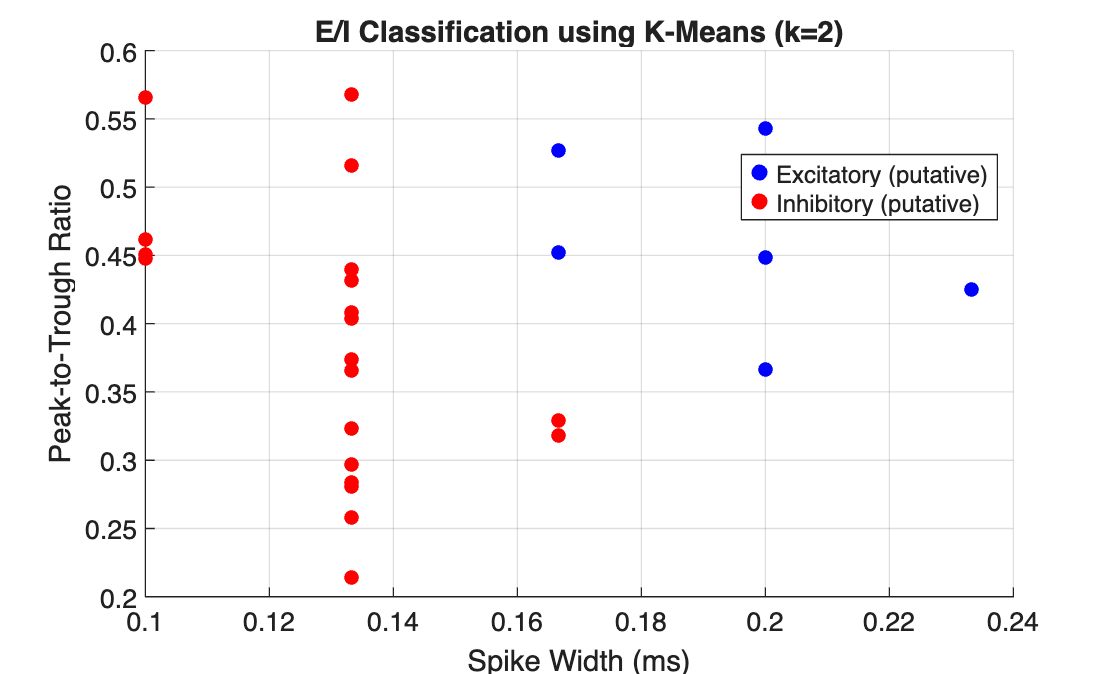

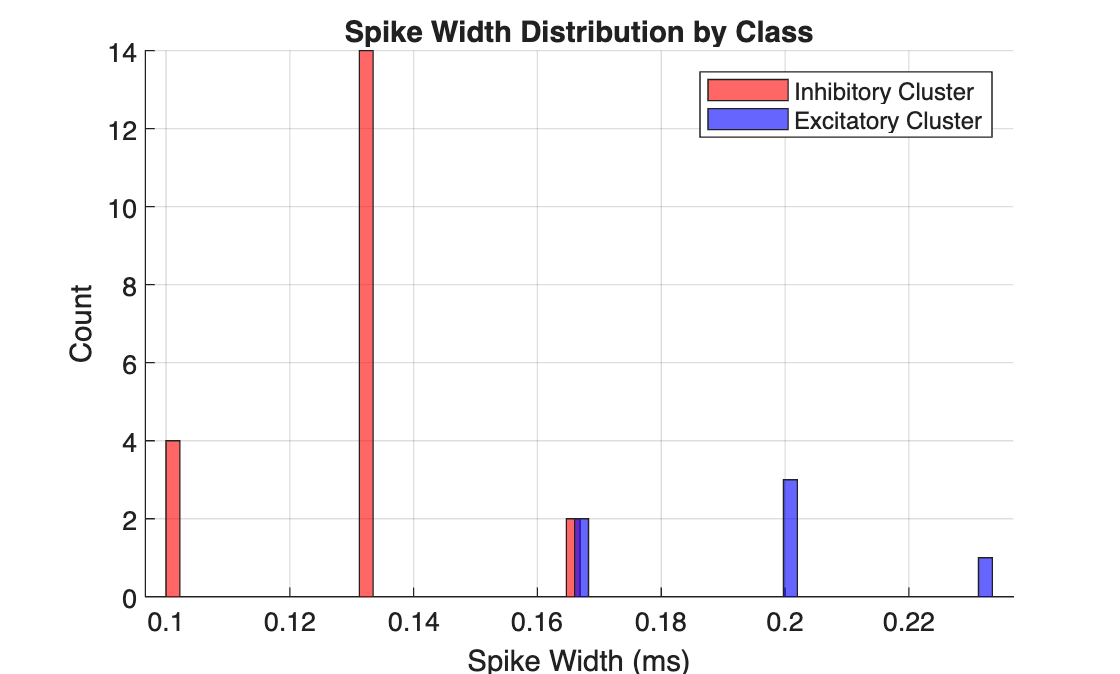

Generated 2 visualization figures.
Generating comprehensive summary...
Enhanced E/I classification complete!

--- Final Classification Summary ---
Total Neurons Analyzed: 26
----------------------------------
Excitatory (Putative):   6 (23.1%)
Inhibitory (Putative):   20 (76.9%)
E/I Ratio:               0.30
----------------------------------


Assigning cortical layers to all valid neurons...
Analyzing spike width distribution for each layer:
  - Layer L5: Found 26 valid neurons.

--- Layer-Aware Bimodality Summary ---
    Layer    NeuronCount    Dip_pValue    GMM_SilhouetteScore    GMM_Threshold_ms    IsBimodal
    _____    ___________    __________    ___________________    ________________    _________

    "L5"         26             1               0.82395                NaN               0    

Generating layer-stratified plots...


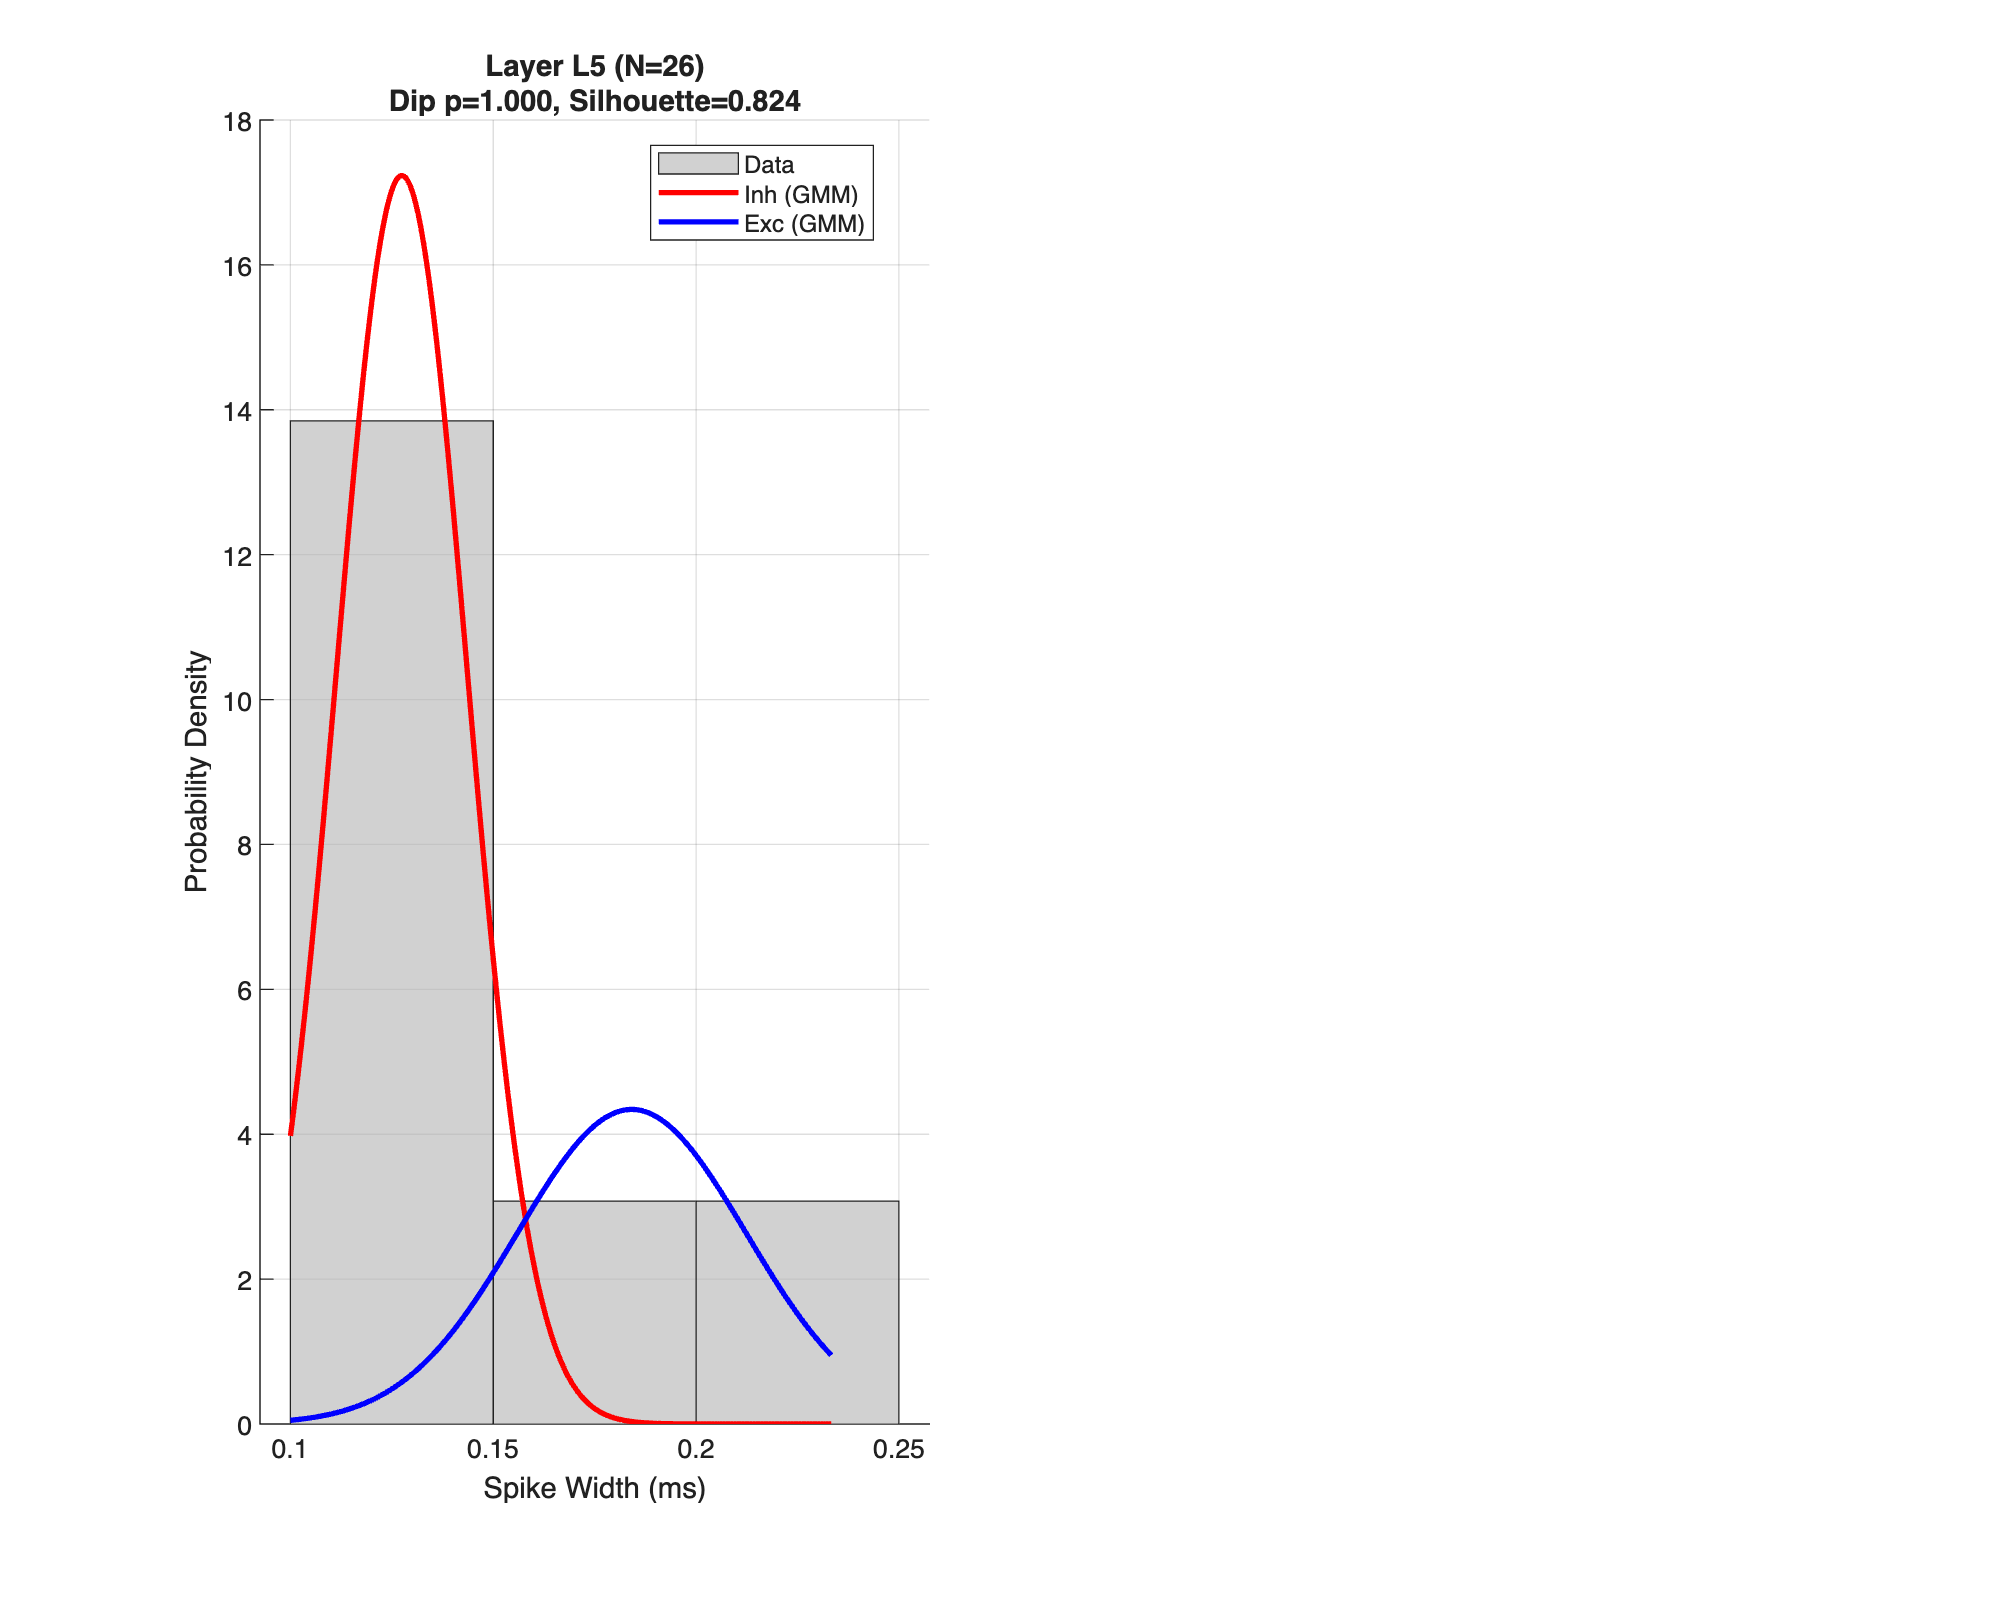

Validating for area: ACA
  Observed E/I Ratio: 0.30 (E=6, I=20)
  Running 5000 permutations...
  Permutation Test P-value: 1.0000
  Result is not statistically significant. The observed E/I ratio could be due to chance.


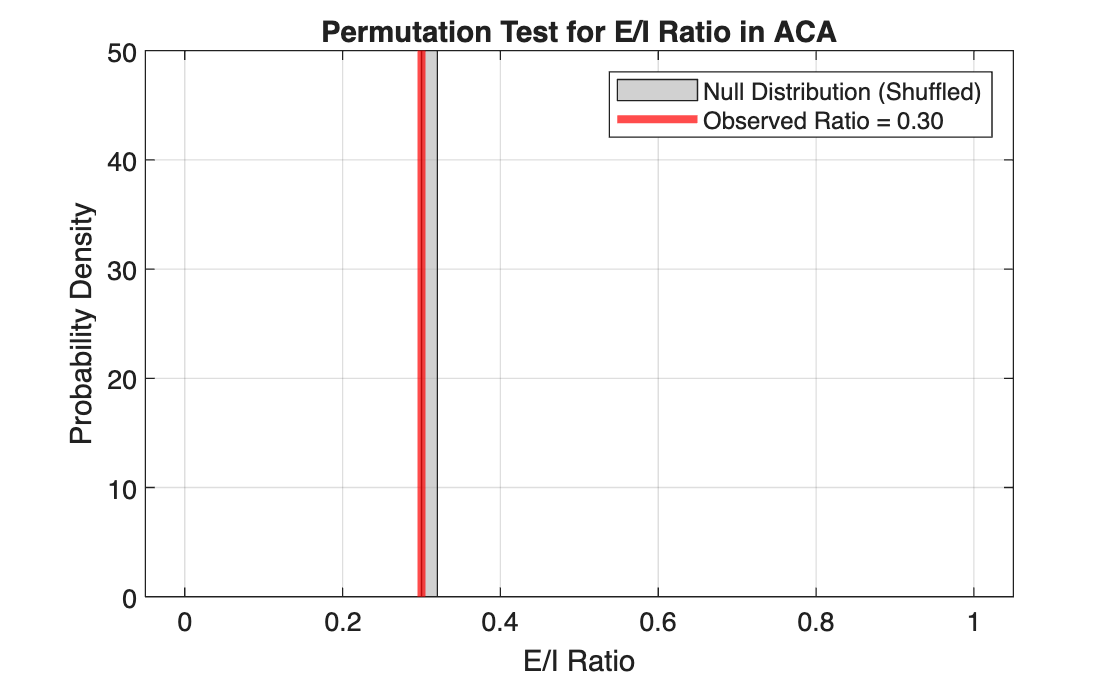

Assigning cortical layers based on channel depth...
Calculating auto- and cross-correlograms for 26 neurons...
Correlation analysis complete. Generating visualizations...


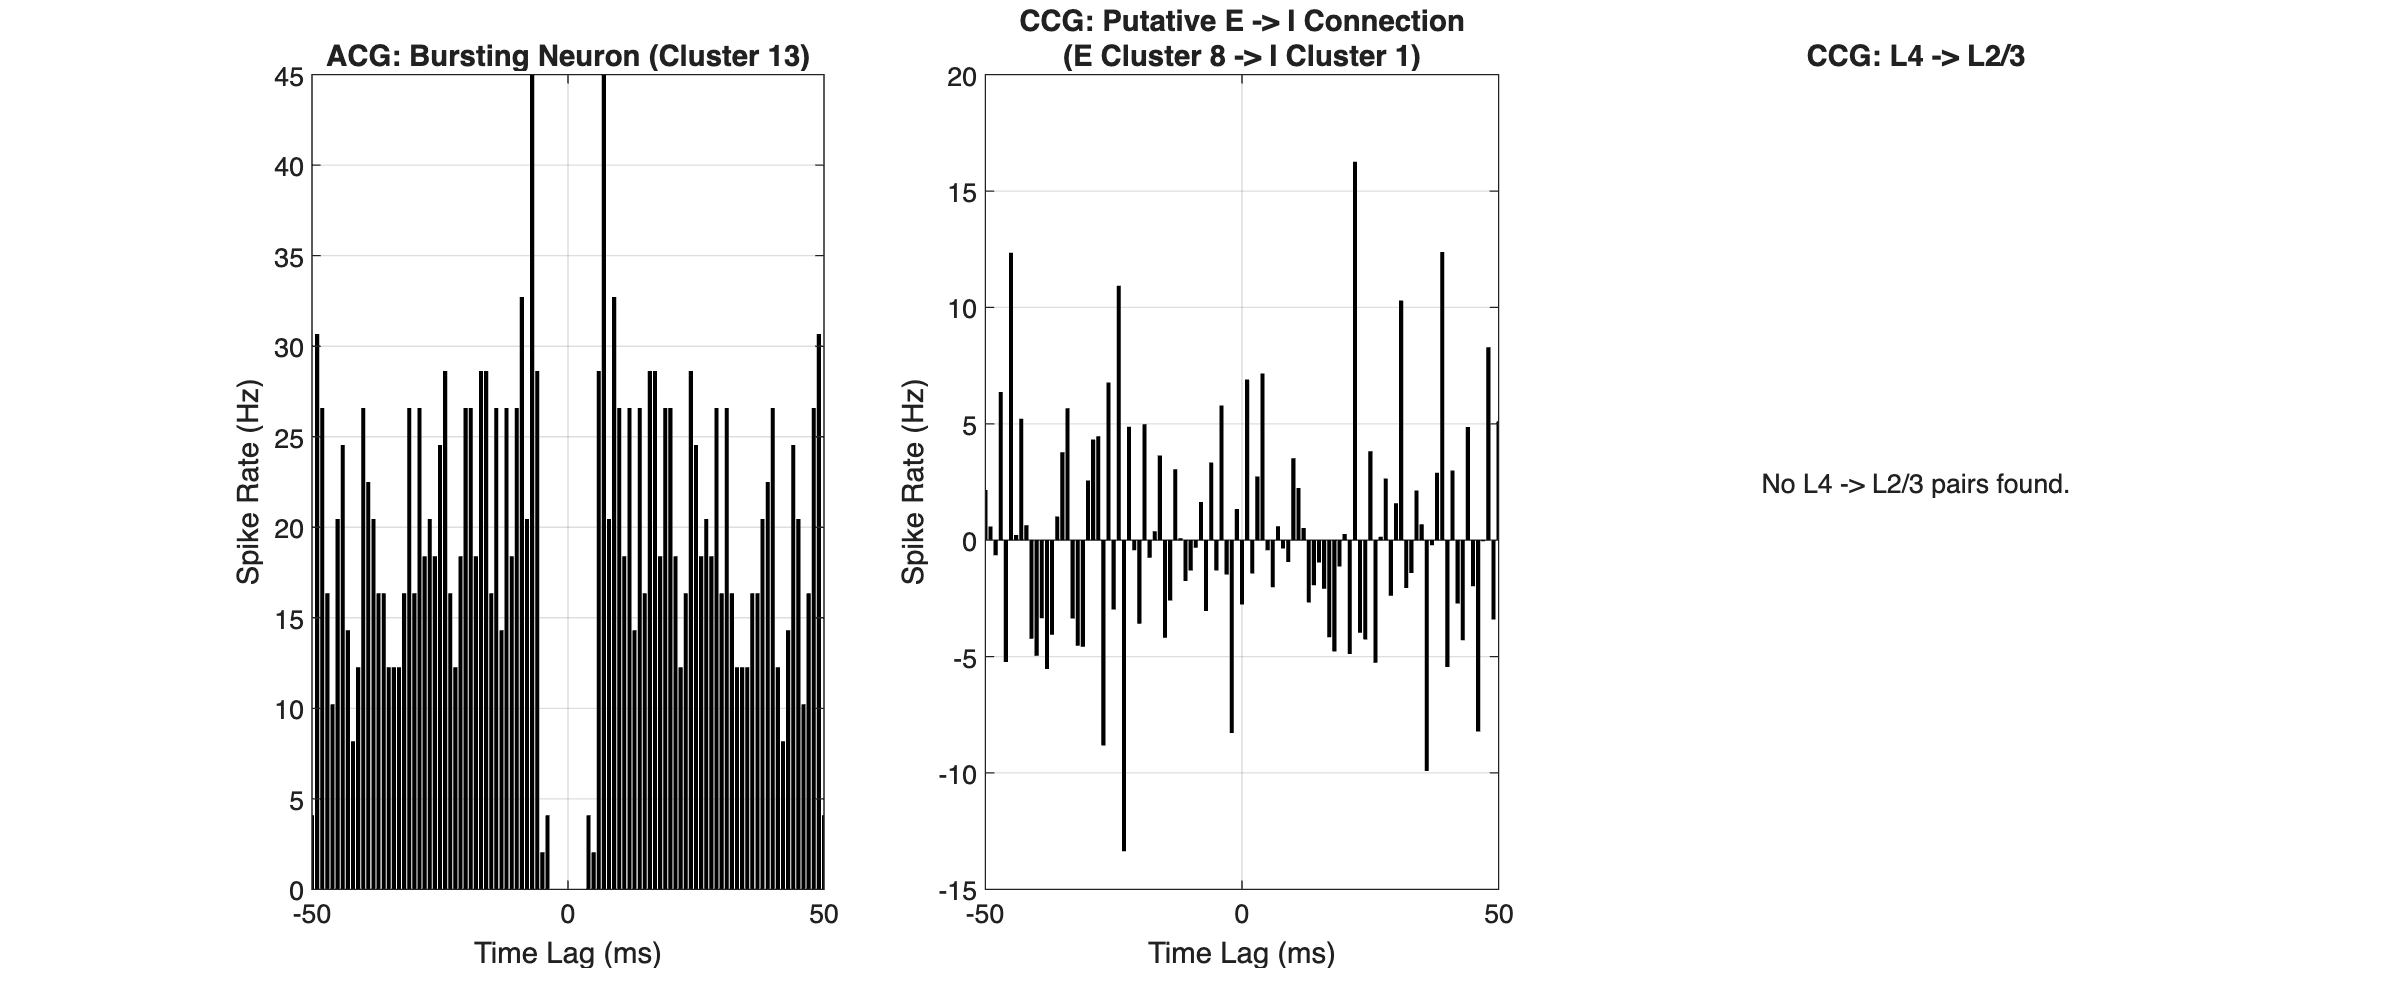

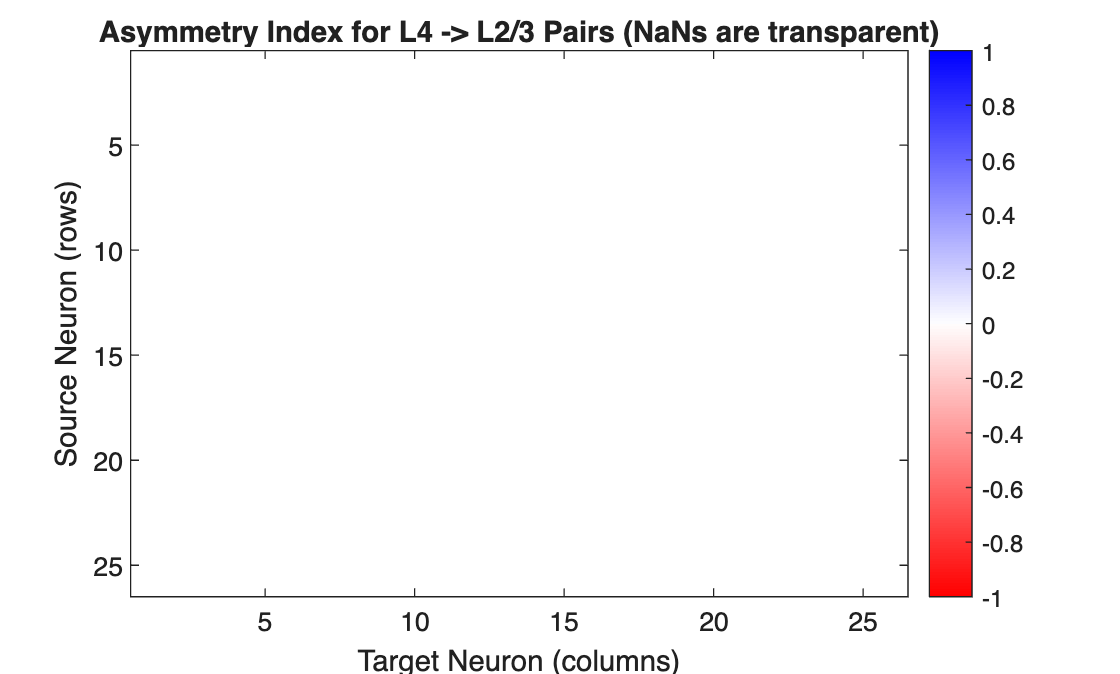

Generated 2 correlation visualization figures.


Processing Brain Region: DP (2 of 11)


Step 7: Filtering for DP spikes...


Created DP data struct with 37 clusters and 424182 spikes.




=== Enhanced E/I Classification Analysis ===
Extracting comprehensive waveform features...
Extracted features from 37/37 valid neurons
Analyzing distribution characteristics...
Distribution Analysis Results:
  Spike Width: Unimodal (p=1.0000)
  Peak-Trough Ratio: Unimodal (p=1.0000)
  Recommended Strategy: percentile_based
Determining optimal classification strategy...
Selecting k-means clustering strategy with 2 features...
Applying enhanced E/I classification...
Running Gaussian Mixture Model (GMM) clustering on 37 neurons...
Classification Results:
  Excitatory: 2 (5.4%)
  Inhibitory: 35 (94.6%)
Validating classification accuracy...
Calculating silhouette score to validate cluster separation...
  Mean Silhouette Score: 0.909
Generating visualization plots...


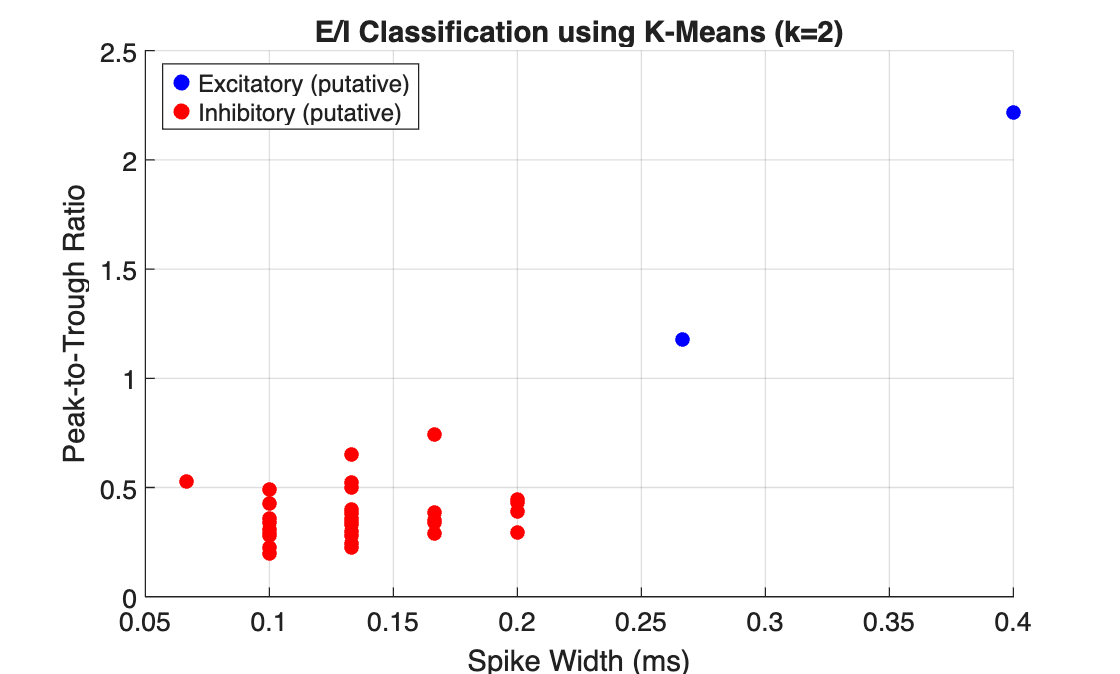

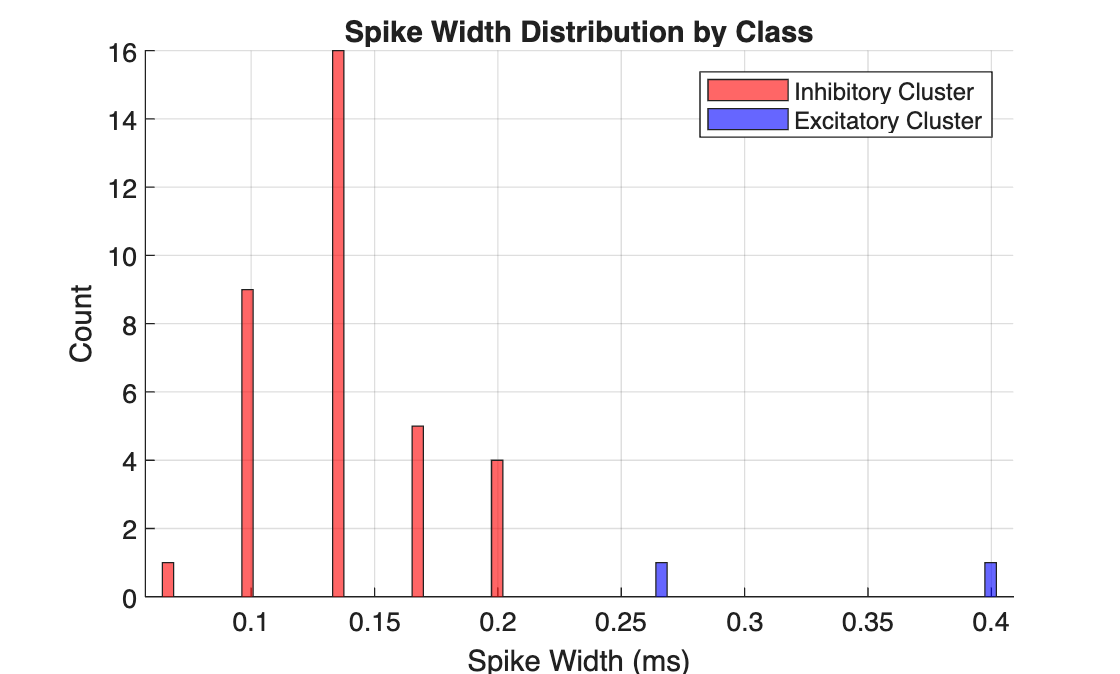

Generated 2 visualization figures.
Generating comprehensive summary...
Enhanced E/I classification complete!

--- Final Classification Summary ---
Total Neurons Analyzed: 37
----------------------------------
Excitatory (Putative):   2 (5.4%)
Inhibitory (Putative):   35 (94.6%)
E/I Ratio:               0.06
----------------------------------


Assigning cortical layers to all valid neurons...
Analyzing spike width distribution for each layer:
  - Layer L2/3: Found 35 valid neurons.
  - Layer L4: Found 2 valid neurons.
    ...Skipping due to insufficient neuron count.

--- Layer-Aware Bimodality Summary ---
    Layer     NeuronCount    Dip_pValue    GMM_SilhouetteScore    GMM_Threshold_ms    IsBimodal
    ______    ___________    __________    ___________________    ________________    _________

    "L2/3"        35              1              0.91481                NaN               0    
    "L4"           2            NaN                  NaN                NaN               0    

Generating layer-stratified plots...


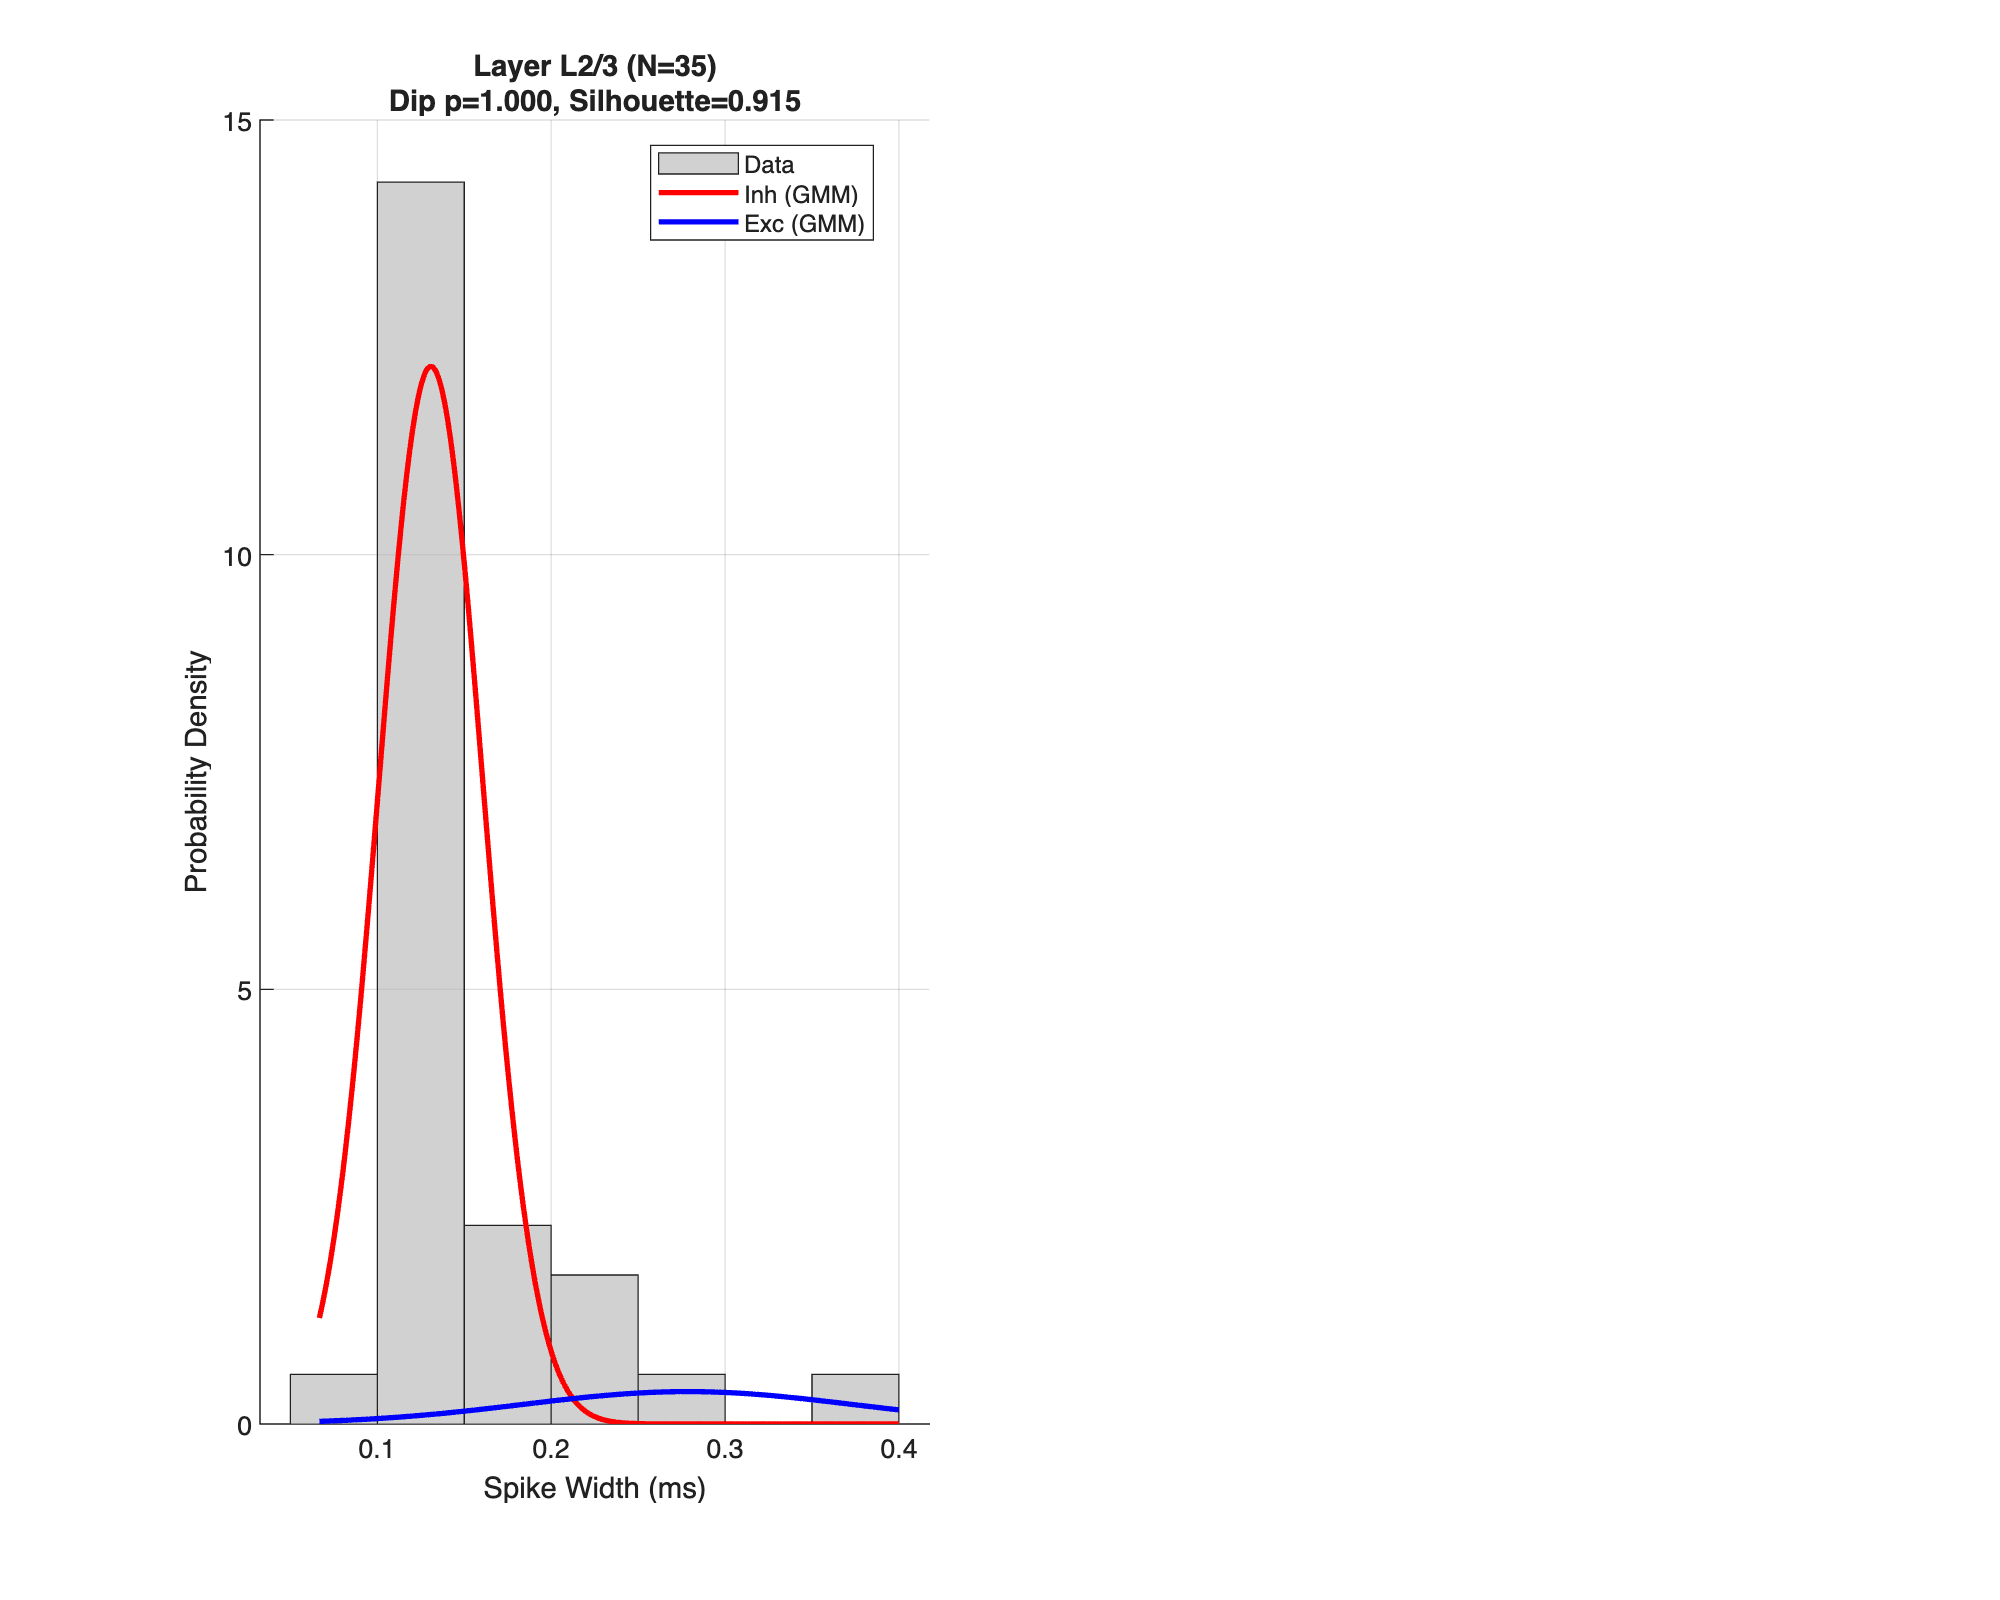

Validating for area: DP
  Observed E/I Ratio: 0.06 (E=2, I=35)
  Running 5000 permutations...
  Permutation Test P-value: 1.0000
  Result is not statistically significant. The observed E/I ratio could be due to chance.


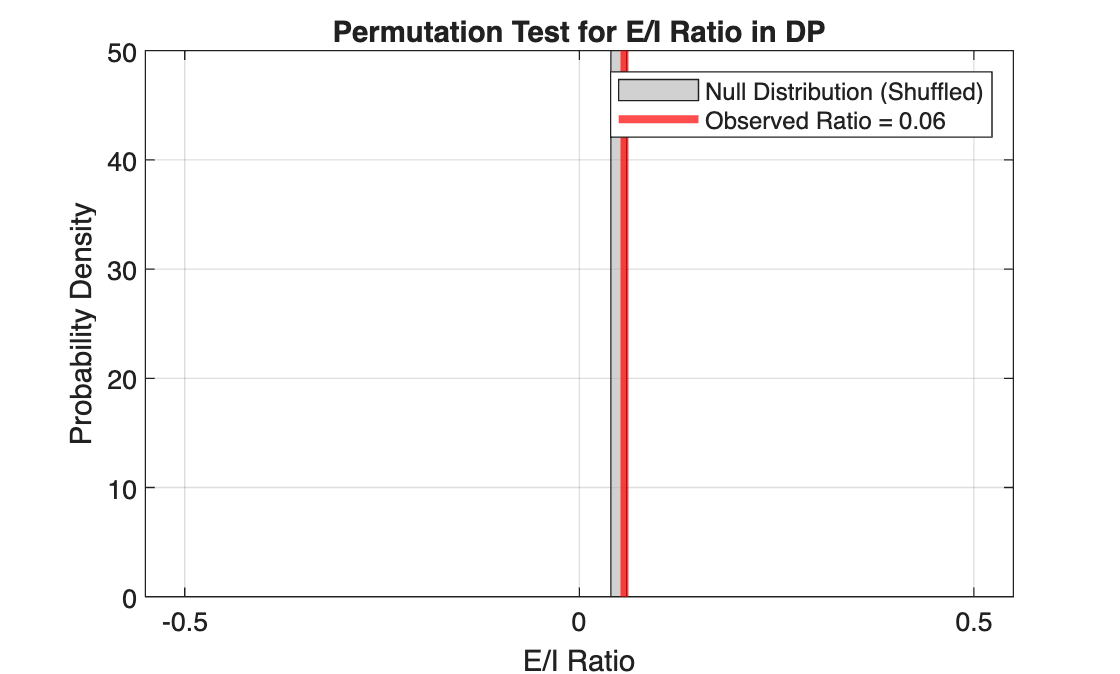

Assigning cortical layers based on channel depth...
Calculating auto- and cross-correlograms for 37 neurons...
Correlation analysis complete. Generating visualizations...


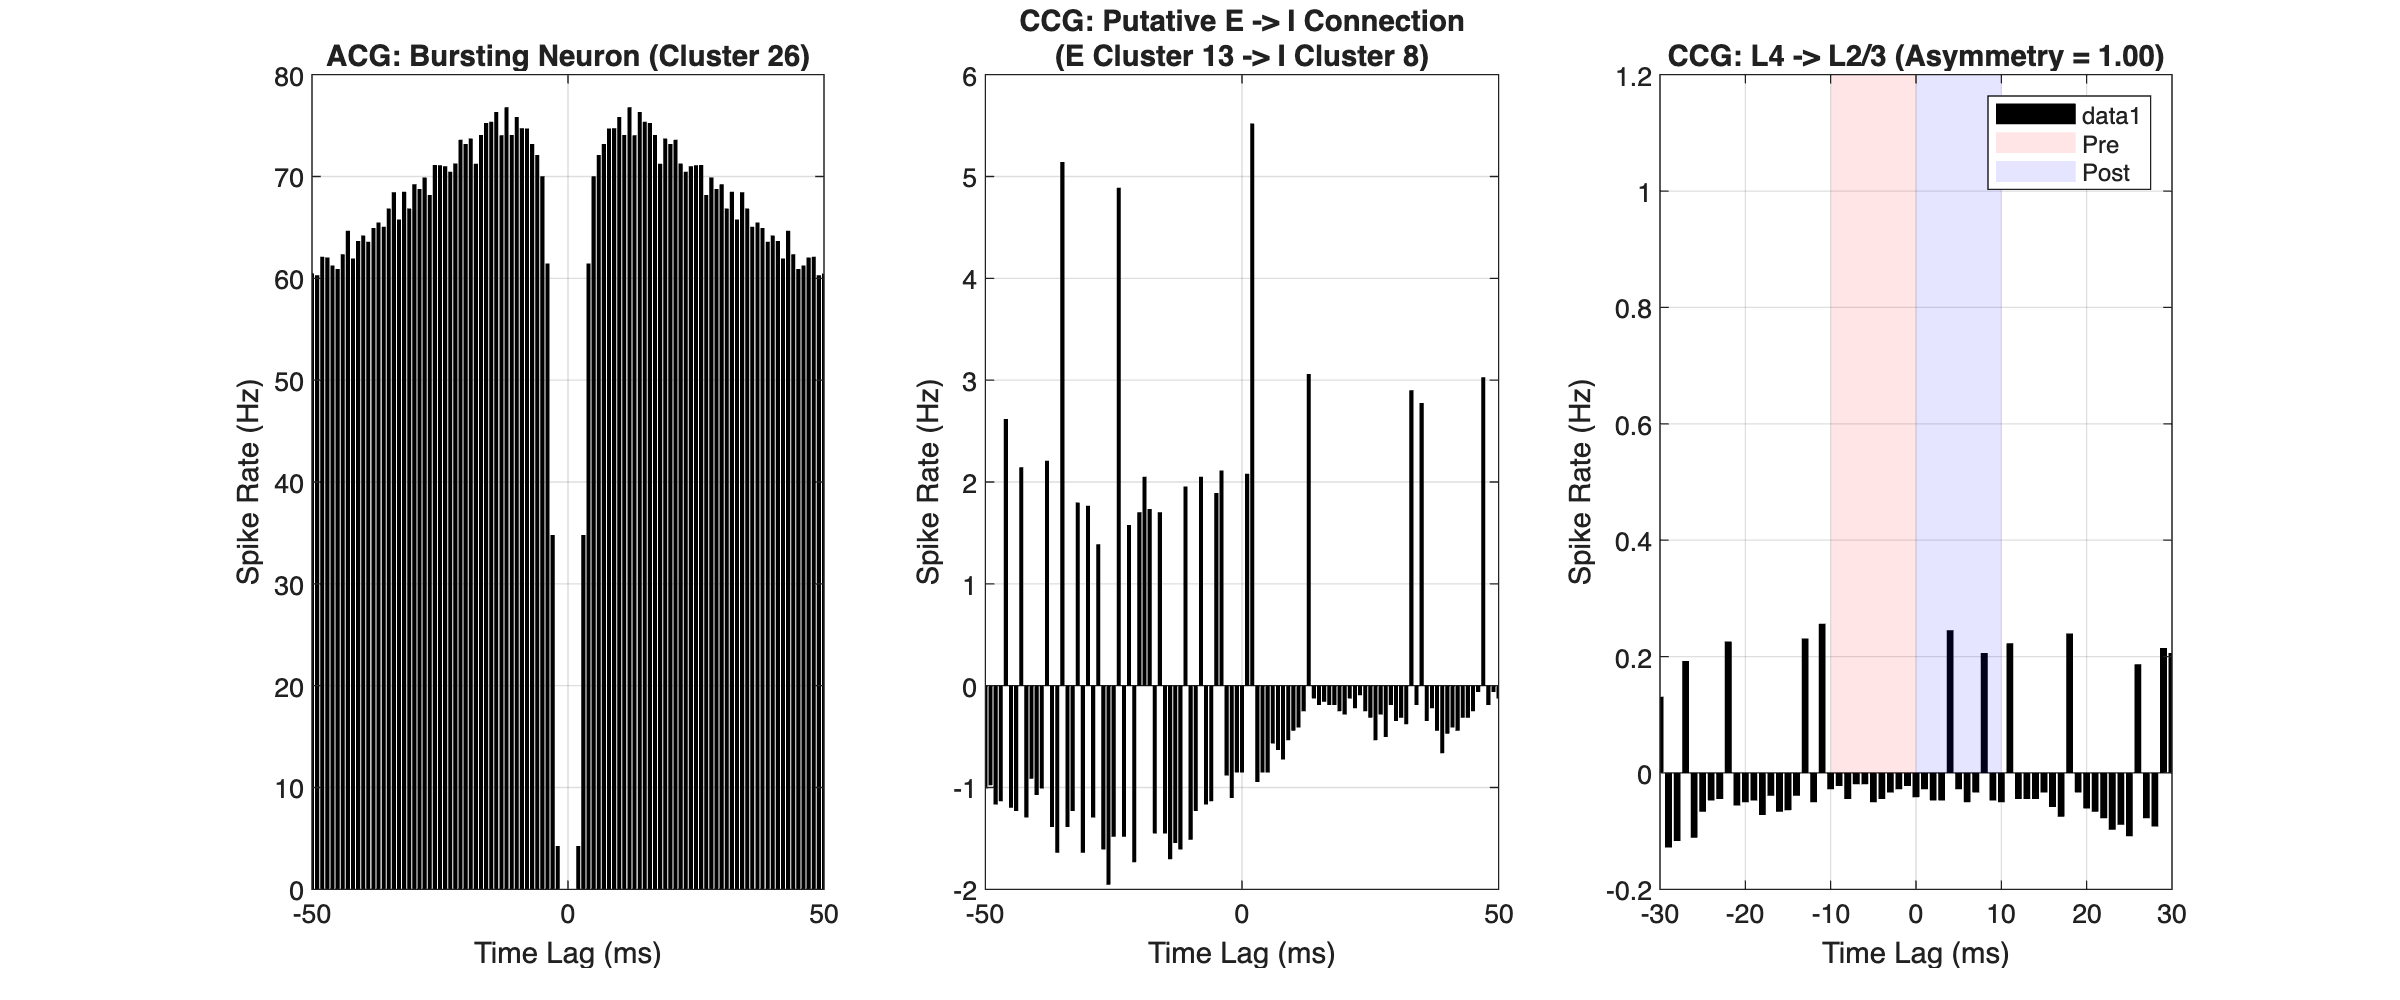

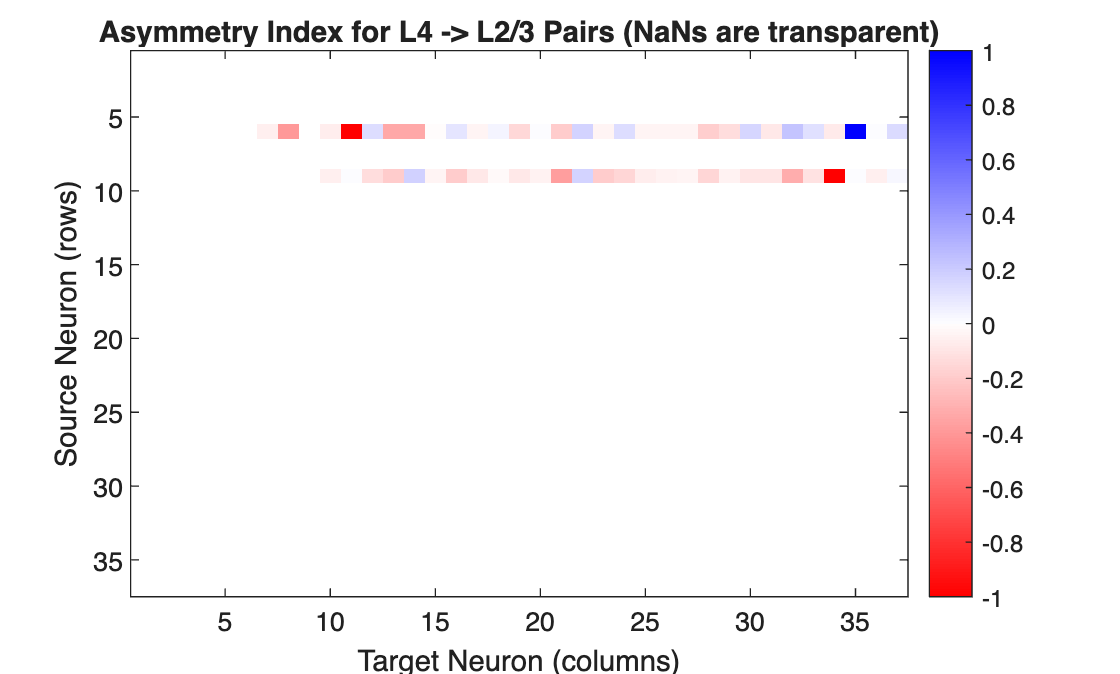

Generated 2 correlation visualization figures.


Processing Brain Region: ILA (3 of 11)


Step 7: Filtering for ILA spikes...


Created ILA data struct with 81 clusters and 1147501 spikes.




=== Enhanced E/I Classification Analysis ===
Extracting comprehensive waveform features...
Extracted features from 81/81 valid neurons
Analyzing distribution characteristics...
Distribution Analysis Results:
  Spike Width: Unimodal (p=1.0000)
  Peak-Trough Ratio: Unimodal (p=1.0000)
  Recommended Strategy: percentile_based
Determining optimal classification strategy...
Selecting k-means clustering strategy with 2 features...
Applying enhanced E/I classification...
Running Gaussian Mixture Model (GMM) clustering on 81 neurons...
Classification Results:
  Excitatory: 68 (84.0%)
  Inhibitory: 13 (16.0%)
Validating classification accuracy...
Calculating silhouette score to validate cluster separation...
  Mean Silhouette Score: -0.110
Generating visualization plots...


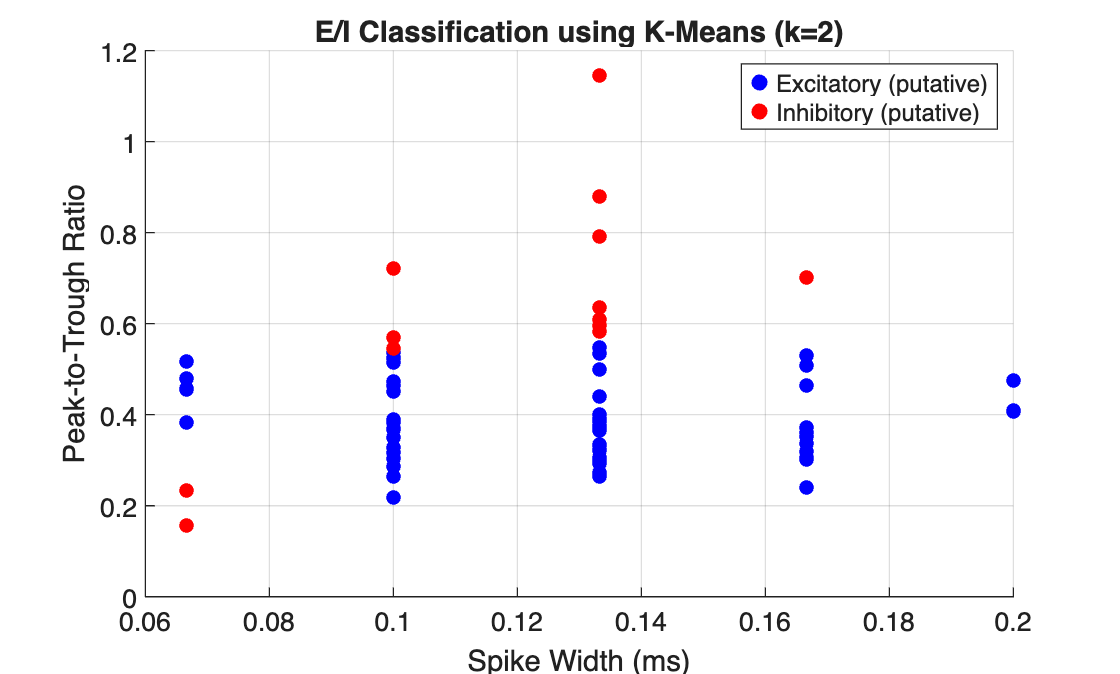

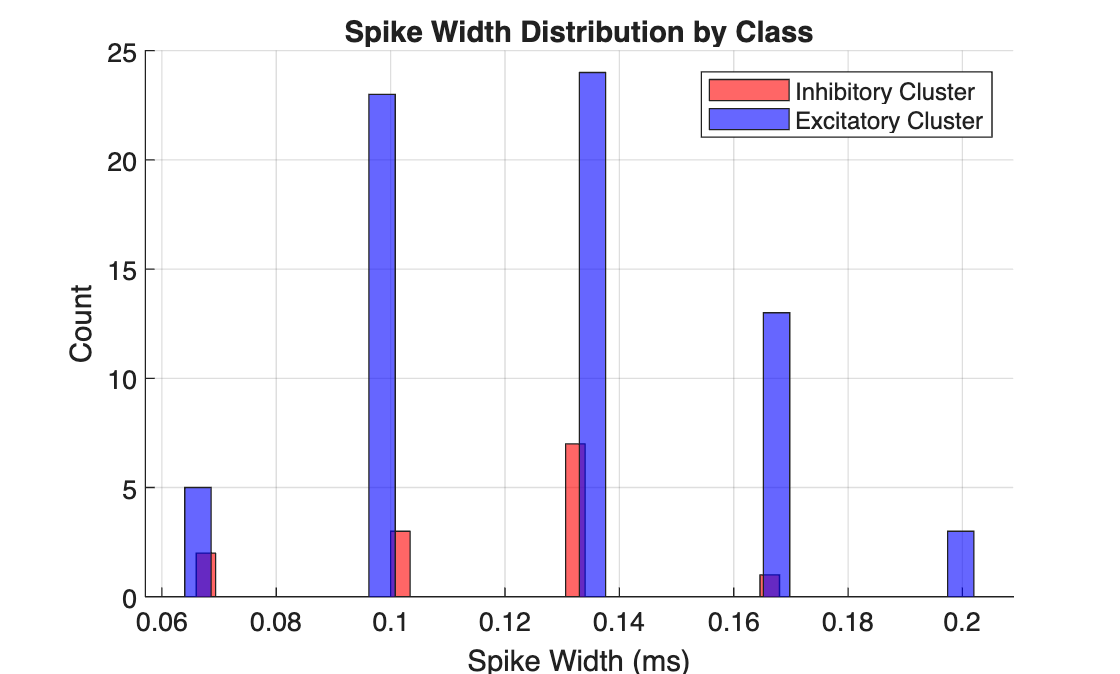

Generated 2 visualization figures.
Generating comprehensive summary...
Enhanced E/I classification complete!

--- Final Classification Summary ---
Total Neurons Analyzed: 81
----------------------------------
Excitatory (Putative):   68 (84.0%)
Inhibitory (Putative):   13 (16.0%)
E/I Ratio:               5.23
----------------------------------


Assigning cortical layers to all valid neurons...
Analyzing spike width distribution for each layer:
  - Layer L4: Found 81 valid neurons.

--- Layer-Aware Bimodality Summary ---
    Layer    NeuronCount    Dip_pValue    GMM_SilhouetteScore    GMM_Threshold_ms    IsBimodal
    _____    ___________    __________    ___________________    ________________    _________

    "L4"         81             1               0.79466                NaN               0    

Generating layer-stratified plots...


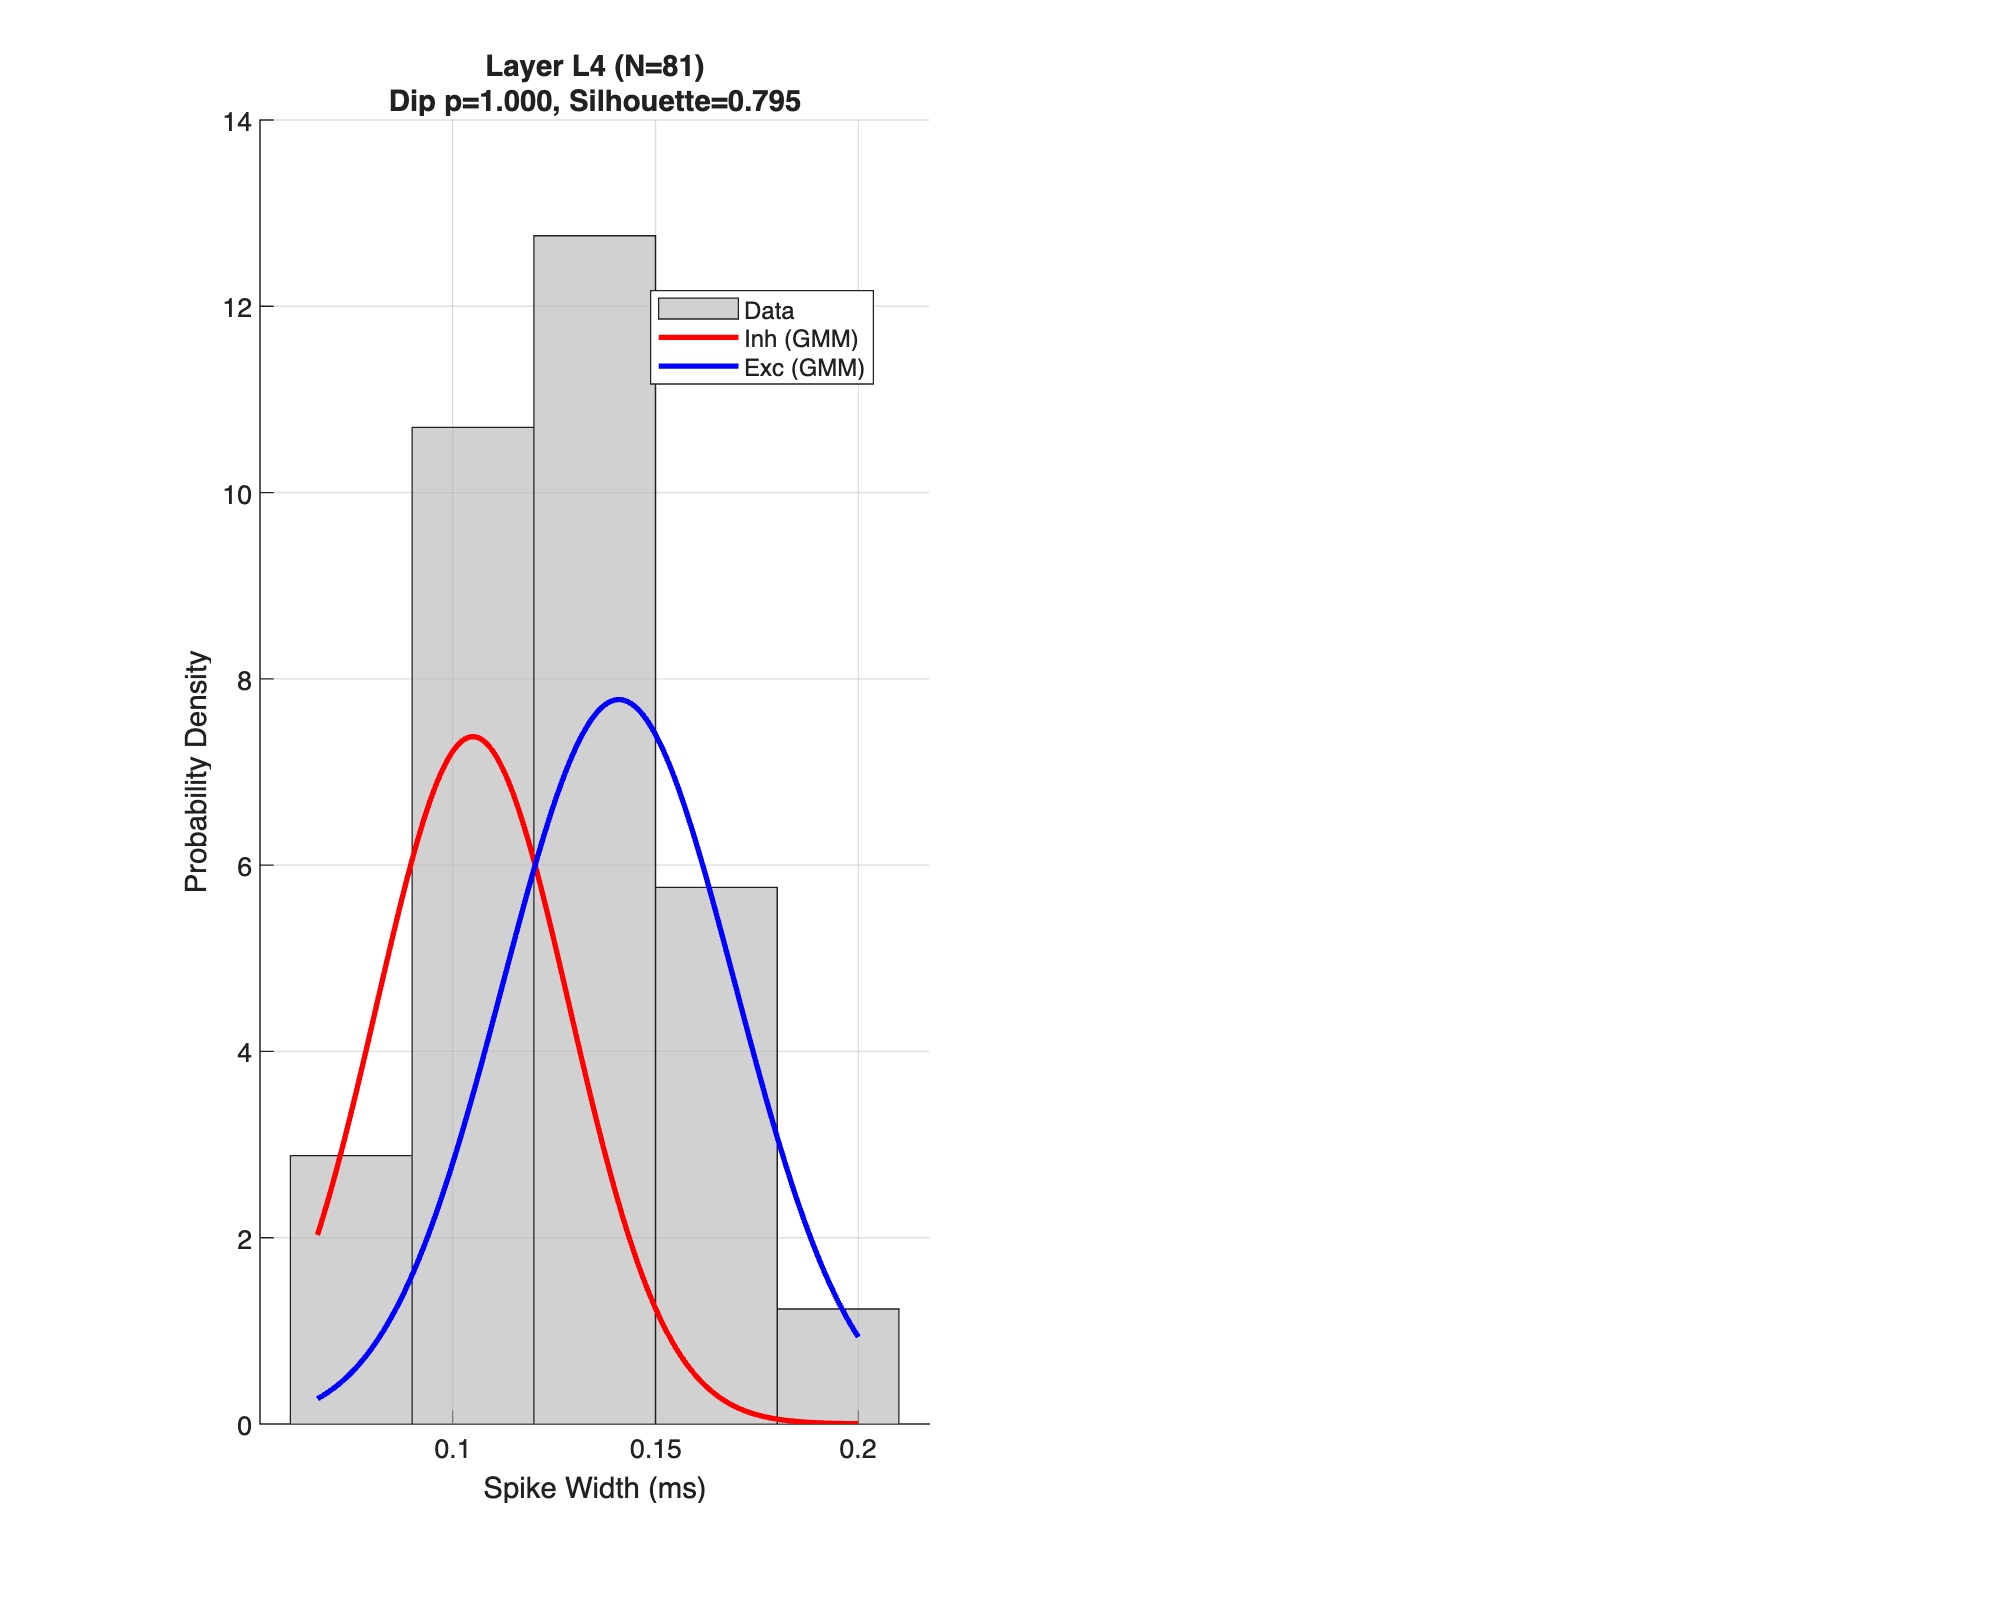

Validating for area: ILA
  Observed E/I Ratio: 5.23 (E=68, I=13)
  Running 5000 permutations...
  Permutation Test P-value: 1.0000
  Result is not statistically significant. The observed E/I ratio could be due to chance.


Assigning cortical layers based on channel depth...
Calculating auto- and cross-correlograms for 81 neurons...


basePath = '/Volumes/COBYB USB/Davis_Lab/Steinmetz_et_al_2019_9974357/nicklab/Subjects/Radnitz/2017-01-08/001/alf/';
spikeTimes = readNPY([basePath 'spikes.times.npy']);
spikeClusters = readNPY([basePath 'spikes.clusters.npy']);
clusterPeakChan = readNPY([basePath 'clusters.peakChannel.npy']);
clusterAnnotation = readNPY([basePath 'clusters._phy_annotation.npy']);
templateWaveforms = readNPY([basePath 'clusters.templateWaveforms.npy']);

% <<< START OF THE NEW LOOP >>>
for i = 1:length(uniqueBrainRegions)
    currentRegion = uniqueBrainRegions{i};
    fprintf('\nProcessing region %d/%d: %s\n', i, length(uniqueBrainRegions), currentRegion);
    fprintf('\n\n=======================================================\n');
    fprintf('Processing Brain Region: %s (%d of %d)\n', currentRegion, i, length(uniqueBrainRegions));
    fprintf('=======================================================\n');

    % Step 7 (Modified): Filter for the CURRENT region's spikes
    fprintf('Step 7: Filtering for %s spikes...\n', currentRegion);

    goodClusters = find(clusterAnnotation >= 2);
    regionChannelMask = strcmp(brainloc.allen_ontology, currentRegion);
    regionChannels = find(regionChannelMask);

    if isempty(regionChannels)
    fprintf('Skipping %s: No channels found.\n', currentRegion);
       continue; % Skip to next region
    end

    regionClusterMask = ismember(clusterPeakChan + 1, regionChannels);
    goodRegionClusters = intersect(goodClusters, find(regionClusterMask));
    
    if length(goodRegionClusters) < 10 % Min neuron threshold
        fprintf('Skipping %s: Insufficient good clusters (%d).\n', currentRegion, length(goodRegionClusters));
     continue;
    end

    regionSpikeMask = ismember(spikeClusters, goodRegionClusters);

    % Create a temporary data struct for this region
    regionData = struct();
    regionData.name = currentRegion;
    regionData.clusters = goodRegionClusters;
    regionData.spikeTimes = spikeTimes(regionSpikeMask);
    regionData.spikeClusterIDs = spikeClusters(regionSpikeMask);
    regionData.waveforms = templateWaveforms(goodRegionClusters, :, :);
    regionData.nClusters = length(goodRegionClusters);
    regionData.nSpikes = sum(regionSpikeMask);
    fprintf('Created %s data struct with %d clusters and %d spikes.\n', currentRegion, regionData.nClusters, regionData.nSpikes);
    
    % Call the validation function
    validateInputData(regionData);
    
    % RUN ALL ANALYSES on the current region's data
    % Note: Passing empty LFP data; this can be adapted later if needed.
    analysisResults = runEnhancedEIClassification(regionData, [], []);


    layerAwareResults = runLayerAwareEIAnalysis(regionData, analysisResults.waveformFeatures, clusterPeakChan, rawRow);
    analysisResults.layerAwareAnalysis = layerAwareResults;
    
    validationResults = validateEIClassification(regionData, analysisResults.enhancedClassification, brainloc, clusterPeakChan, currentRegion, 5000);
    analysisResults.permutationTest = validationResults;
    
    correlationAnalysis = runSpikeCorrelationAnalysis(regionData, analysisResults, clusterPeakChan, rawRow);
    analysisResults.correlationAnalysis = correlationAnalysis;
    
    % --- NEW CODE TO STORE RESULTS ---
    % Sanitize the region name to use as a struct field name
    cleanRegionName = strrep(currentRegion, '/', '_'); 

    % Store all results in the master struct
    allRegionResults.(cleanRegionName) = analysisResults;
    allRegionResults.(cleanRegionName).rawData = regionData;

 end % <<< END OF THE NEW LOOP >>>


    fprintf('\n\n=== All brain regions processed! ===\n');

## ########################################################################

## HELPER FUNCTIONS (All function definitions must be at the end of the script)

## ########################################################################

##  --- LFP Loading Function ---

function data = load_lfp_rows(filename, nChannels, rowIdx)
    % filename : full path to .lf.bin
    % nChannels: number of recorded channels
    % rowIdx   : which rows you want (e.g. VISp rows)
    % Returns: matrix [length(rowIdx) x nTimepoints]
    fid = fopen(filename, 'r');
    raw = fread(fid, [nChannels, Inf], 'int16=>double'); % load all channels
    fclose(fid);
    data = raw(rowIdx+1, :);  % MATLAB is 1-indexed, rawRow is 0-indexed
end



## --- Step 9: Enhanced Excitatory/Inhibitory Classification System ---

The runEnhancedEIClassification function orchestrates a series of steps to classify neural waveform data 

 into excitatory and inhibitory categories. It begins by extracting waveform features from the provided data,

 then analyzes the distribution characteristics of these features. Based on this analysis, it determines 

 the best classification strategy to apply. The function then executes the classification, validates the 

 results, and generates visualizations to illustrate the findings. Finally, it compiles all results into a 

 structured output for further analysis or reporting.


function enhancedResults = runEnhancedEIClassification(v1Data, vispLFP, timeVector)
    % Main function to run the enhanced E/I classification
    fprintf('\n\n=== Enhanced E/I Classification Analysis ===\n');
    
    % Extract waveform features
    %   The function calls extractComprehensiveWaveformFeatures to obtain relevant features from the input data,
    %   which are essential for classification.
    fprintf('Extracting comprehensive waveform features...\n');
    waveformFeatures = extractComprehensiveWaveformFeatures(v1Data);
    
    % Detect distribution modality
    %   This step analyzes the characteristics of the extracted features to understand their distribution, 
    %   which is crucial for determining the classification approach.
    fprintf('Analyzing distribution characteristics...\n');
    distributionAnalysis = analyzeDistributionModality(waveformFeatures);
    
    % Determine optimal classification strategy
    %   Based on the waveform features and their distribution, this line determines the optimal strategy 
    %   for classification.
    fprintf('Determining optimal classification strategy...\n');
    classificationStrategy = determineClassificationStrategy(waveformFeatures, distributionAnalysis);
    
    % Apply enhanced classification
    %   The function applies the chosen classification strategy to the waveform features to classify them as excitatory or inhibitory.
    fprintf('Applying enhanced E/I classification...\n');
    enhancedClassification = applyEnhancedClassification(waveformFeatures, classificationStrategy);
    
    % Validate results (using placeholder)
    fprintf('Validating classification accuracy...\n');
    validationResults = validateClassificationAccuracy(enhancedClassification, waveformFeatures);
    
    % Generate comprehensive plots
    fprintf('Generating visualization plots...\n');
    visualizationFigures = generateEnhancedClassificationPlots(waveformFeatures, enhancedClassification);
    
    % Compile results
    %   Here, all relevant results are compiled into a structured output, making it easy to access and review the findings.
    enhancedResults = struct();
    enhancedResults.waveformFeatures = waveformFeatures;
    enhancedResults.distributionAnalysis = distributionAnalysis;
    enhancedResults.classificationStrategy = classificationStrategy;
    enhancedResults.enhancedClassification = enhancedClassification;
    enhancedResults.validationResults = validationResults;
    enhancedResults.visualizationFigures = visualizationFigures;
    enhancedResults.summary = generateClassificationSummary(enhancedClassification, validationResults);
    
    fprintf('Enhanced E/I classification complete!\n');
    printSummaryResults(enhancedResults.summary);
end


    %   The extractComprehensiveWaveformFeatures function processes neural waveform data to compute a range of features
    %   that are useful for analyzing and classifying neural spikes. It initializes arrays to store features for each cluster of waveforms. The function iterates through 
    %   each cluster, calculates the desired features, and handles any errors that may arise during processing. 
    %   The results are stored in a structured format, allowing for easy access and further analysis.
function features = extractComprehensiveWaveformFeatures(v1Data)
    % Extract comprehensive waveform features for classification
    nClusters = v1Data.nClusters;
    features = struct();
    
    % Initialize feature arrays
    features.spikeWidth = zeros(nClusters, 1);
    features.peakToTroughRatio = zeros(nClusters, 1);
    features.peakToTroughLatency = zeros(nClusters, 1);
    features.troughTopeak = zeros(nClusters, 1);
    features.amplitude = zeros(nClusters, 1);
    features.asymmetryIndex = zeros(nClusters, 1);
    features.repolarizationSlope = zeros(nClusters, 1);
    features.afterHyperpolarization = zeros(nClusters, 1);
    features.waveformEnergy = zeros(nClusters, 1);
    features.validNeurons = false(nClusters, 1);
    features.clusterIDs = v1Data.clusters;
    
    % Sampling parameters
    %   The sampling rate is set, and the time step is calculated to convert the sampling frequency into milliseconds, 
    %   which will be used in feature calculations.

    samplingRate = 30000; % AP band sampling rate (Hz)
    %   If the original Local Field Potential (LFP) recording was sampled at 2,500 Hz, using a higher
    %   sampling rate, such as 30,000 Hz, may be necessary for specific analyses, 
    %   particularly when examining high-frequency components like action potentials.
    %   The higher sampling rate allows for better resolution of rapid changes in the waveform, which is essential for extracting features such as spike width and peak-to-trough ratios.
    timeStep = 1/samplingRate * 1000; % Convert to ms
    
    % The function iterates over each cluster of waveforms. 
    %   It uses a try-catch block to handle potential errors gracefully. 
    %   The waveform for the current cluster is extracted.
    %   Feature Calculations: Inside the loop, various features are calculated:
    %       Spike Width: Calculated as the full width at half maximum (FWHM).
    %       Peak-to-Trough Ratio: The ratio of peak value to the absolute trough value.
    %       Latencies and Amplitude: Calculated based on indices of the peak and trough.
    %       Asymmetry Index: A custom function is called to compute this feature.
    %       Repolarization Slope and After Hyperpolarization: These are derived from the waveform characteristics.
    %       Waveform Energy: The sum of squares of the waveform values.
    for i = 1:nClusters
        try
            waveform = squeeze(v1Data.waveforms(i, :, 1));
            [troughVal, troughIdx] = min(waveform);
            [peakVal, peakIdx] = max(waveform);
            
            if isnan(troughVal) || isnan(peakVal) || troughVal >= peakVal
                continue;
            end
            
            features.validNeurons(i) = true;
            
            % Spike Width (FWHM)
            halfTrough = troughVal / 2;
            belowHalf = find(waveform <= halfTrough);
            if length(belowHalf) >= 2
                features.spikeWidth(i) = (belowHalf(end) - belowHalf(1)) * timeStep;
            else
                features.spikeWidth(i) = NaN;
            end
            
            % Peak-to-Trough Ratio
            if abs(troughVal) > eps
                features.peakToTroughRatio(i) = peakVal / abs(troughVal);
            else
                features.peakToTroughRatio(i) = NaN;
            end
            
            features.peakToTroughLatency(i) = abs(peakIdx - troughIdx) * timeStep;
            features.troughTopeak(i) = (peakIdx - troughIdx) * timeStep;
            features.amplitude(i) = peakVal - troughVal;
            features.asymmetryIndex(i) = calculateAsymmetryIndex(waveform, troughIdx);
            
            if peakIdx > troughIdx
                features.repolarizationSlope(i) = (peakVal - troughVal) / ((peakIdx - troughIdx) * timeStep);
            else
                features.repolarizationSlope(i) = NaN;
            end
            
            if peakIdx < length(waveform)
                postPeakMin = min(waveform(peakIdx:end));
                features.afterHyperpolarization(i) = peakVal - postPeakMin;
            else
                features.afterHyperpolarization(i) = NaN;
            end
            
            features.waveformEnergy(i) = sum(waveform.^2);
            
        catch ME
            fprintf('Warning: Error processing cluster %d: %s\n', i, ME.message);
            continue;
        end
    end
    fprintf('Extracted features from %d/%d valid neurons\n', sum(features.validNeurons), nClusters);
end

    %   The analyzeDistributionModality function evaluates the distribution characteristics of neuron 
    %   features by checking for valid data points and performing statistical tests to determine if 
    %   the distributions are unimodal or bimodal. If there are insufficient valid neurons, it warns 
    %   the user and suggests a fallback strategy. The function then tests the bimodality of the spike 
    %   width and peak-to-trough ratio, analyzes combined features, and recommends a strategy based on the results. 
    %   Finally, it prints the analysis results, including modality types and p-values.
function distAnalysis = analyzeDistributionModality(features)
    distAnalysis = struct();
    % Here, validIdx is created to identify valid neurons by checking three conditions: 
    % the neuron must be valid, the spike width must not be NaN, and it must be greater than zero.
    validIdx = features.validNeurons & ~isnan(features.spikeWidth) & features.spikeWidth > 0;
  
    % If there are fewer than 10 valid neurons, a warning is printed,
    % and the function sets isValid to false, assigns a fallback strategy, and exits early.
    if sum(validIdx) < 10
        fprintf('Warning: Insufficient valid neurons for distribution analysis\n');
        distAnalysis.isValid = false;
        distAnalysis.recommendedStrategy = 'default_literature'; % Fallback strategy
        return;
    end
    % If there are enough valid neurons, the function sets isValid to true and extracts
    % the spike widths and peak-to-trough ratios corresponding to valid neurons.
    distAnalysis.isValid = true;
    spikeWidths = features.spikeWidth(validIdx);
    peakTroughRatios = features.peakToTroughRatio(validIdx);
    
    distAnalysis.spikeWidth = testBimodality(spikeWidths, 'Spike Width');
    distAnalysis.peakTroughRatio = testBimodality(peakTroughRatios, 'Peak-to-Trough Ratio');
    distAnalysis.combinedFeatures = analyzeCombinedFeatures(spikeWidths, peakTroughRatios);
    distAnalysis.recommendedStrategy = determineDistributionStrategy(distAnalysis);
    
    fprintf('Distribution Analysis Results:\n');
    fprintf('  Spike Width: %s (p=%.4f)\n', distAnalysis.spikeWidth.modalityType, distAnalysis.spikeWidth.pValue);
    fprintf('  Peak-Trough Ratio: %s (p=%.4f)\n', distAnalysis.peakTroughRatio.modalityType, distAnalysis.peakTroughRatio.pValue);
    fprintf('  Recommended Strategy: %s\n', distAnalysis.recommendedStrategy);
end

function classificationStrategy = determineClassificationStrategy(~, ~)
    % Determine the optimal classification strategy.
    % For this pipeline, we will use a more robust 2D k-means clustering approach.
    
    fprintf('Selecting k-means clustering strategy with 2 features...\n');
    classificationStrategy = struct(); 
    %   The method for classification is set to 'kmeans_2D', 
    %   and the features used for clustering are specified as a cell array containing spikeWidth and peakToTroughRatio. 
    %   This structure allows for easy access to the classification method and the features later in the code.
    classificationStrategy.method = 'kmeans_2D';
    classificationStrategy.features = {'spikeWidth', 'peakToTroughRatio'};
end

    %   The applyEnhancedClassification function takes neuron feature data and a classification strategy as inputs. 
    %   It uses GMM clustering to categorize neurons into excitatory and inhibitory groups based on their spike width and peak-to-trough ratio. 
    function classification = applyEnhancedClassification(features, strategy)
    % Applies a 2D Gaussian Mixture Model (GMM) to classify neurons.
    
    classification = struct();
    nNeurons = length(features.validNeurons);
    
    % Initialize outputs
    classification.isExcitatory = false(nNeurons, 1);
    classification.isInhibitory = false(nNeurons, 1);
    classification.isUnclassified = true(nNeurons, 1);
    classification.strategy = strategy; 

    % --- GMM Clustering ---
    % 1. Prepare the data for clustering from valid neurons
    validIdx = features.validNeurons & ~isnan(features.spikeWidth) & ~isnan(features.peakToTroughRatio);
    featureData = [features.spikeWidth(validIdx), features.peakToTroughRatio(validIdx)];
    
    if size(featureData, 1) < 10 % GMM needs a few points to converge
        fprintf('Warning: Not enough valid neurons for GMM clustering.\n');
        return;
    end
    
    % 2. Run GMM to find 2 clusters (putative E and I)
    fprintf('Running Gaussian Mixture Model (GMM) clustering on %d neurons...\n', size(featureData, 1));
    options = statset('MaxIter', 1000);
    
    % --- FIX IS HERE ---
    % Added 'RegularizationValue' to prevent ill-conditioned covariance error
    try
        gmm_model = fitgmdist(featureData, 2, 'Options', options, 'RegularizationValue', 1e-5);
    catch ME
        fprintf('Warning: GMM clustering failed for this region: %s\n', ME.message);
        % As a fallback, you could use kmeans here if you wanted
        % For now, we will just return and leave neurons as unclassified
        return;
    end
    
    % 3. Get the posterior probabilities for each neuron belonging to each cluster
    posterior_probs = posterior(gmm_model, featureData);
    
    % 4. Identify which cluster is inhibitory (has the narrower mean spike width)
    [~, inhClusterNum] = min(gmm_model.mu(:, 1)); % Find index of the mean with smaller spike width
    
    % 5. Create final classification masks based on which probability is higher
    validIndices = find(validIdx);
    for i = 1:length(validIndices)
        neuronIdx = validIndices(i);
        % Assign neuron to the cluster for which it has the highest posterior probability
        [~, assignedCluster] = max(posterior_probs(i, :));
        if assignedCluster == inhClusterNum
            classification.isInhibitory(neuronIdx) = true;
        else
            classification.isExcitatory(neuronIdx) = true;
        end
    end
    classification.isUnclassified(validIdx) = false;
    classification.gmm_model = gmm_model; % Save the model for inspection
    
    % 6. Generate Summary Stats
    summary = struct();
    summary.nExcitatory = sum(classification.isExcitatory);
    summary.nInhibitory = sum(classification.isInhibitory);
    nValid = summary.nExcitatory + summary.nInhibitory;
    
    if nValid > 0
        summary.percentExcitatory = 100 * summary.nExcitatory / nValid;
        summary.percentInhibitory = 100 * summary.nInhibitory / nValid;
    else
        summary.percentExcitatory = 0;
        summary.percentInhibitory = 0;
    end
if summary.nInhibitory > 0
    summary.EIRatio = summary.nExcitatory / summary.nInhibitory;
else
    summary.EIRatio = Inf; % Assign Infinity if no inhibitory neurons are found
end
    
    classification.summary = summary;
        
    fprintf('Classification Results:\n');
    fprintf('  Excitatory: %d (%.1f%%)\n', classification.summary.nExcitatory, classification.summary.percentExcitatory);
    fprintf('  Inhibitory: %d (%.1f%%)\n', classification.summary.nInhibitory, classification.summary.percentInhibitory);
end
    



**--- Other Helper Functions for the E/I system ---**


function modalityTest = testBimodality(data, ~)
    % Simplified bimodality test using Hartigan's Dip Test
    modalityTest = struct();
    %   The function removes any NaN (not-a-number) or infinite values
    %   from the dataset to ensure that only valid data points are analyzed.
    data = data(~isnan(data) & isfinite(data));
    %   If the cleaned dataset contains fewer than 10 data points, the function 
    %   sets the modality type to 'Insufficient_Data' and assigns a p-value of 1, indicating that no meaningful test can be performed.
    if length(data) < 10
        modalityTest.modalityType = 'Insufficient_Data';
        modalityTest.pValue = 1;
        return;
    end
    
    % NOTE: hartigansdipsigniftest is from a File Exchange toolbox.
    % If you don't have it, this will error. A basic check can be substituted.
    % as of 09/17/25 this has been downloaded.
    try
        [~, pValue] = hartigansdipsigniftest(data, 500); 
        modalityTest.pValue = pValue;
        if pValue < 0.05
            modalityTest.modalityType = 'Bimodal';
        else
            modalityTest.modalityType = 'Unimodal';
        end
    catch
        warning('Hartigan''s Dip Test not found. Assuming unimodal distribution.');
        modalityTest.modalityType = 'Unimodal';
        modalityTest.pValue = 1;
    end
end

Commenting resumes here:

function combinedAnalysis = analyzeCombinedFeatures(~, ~)
    % Placeholder, can be expanded for 2D analysis
    combinedAnalysis.prefersBimodal2D = false;
end

%   If the analysis is valid and the spike width is classified as bimodal, it selects a strategy specific to bimodal distributions;
%   otherwise, it defaults to a percentile-based strategy. 
function strategy = determineDistributionStrategy(distAnalysis)
    % Simplified strategy determination
    if ~distAnalysis.isValid
        strategy = 'insufficient_data';
        return;
    end
    
    if strcmp(distAnalysis.spikeWidth.modalityType, 'Bimodal')
        strategy = 'spike_width_bimodal';
    else
        strategy = 'percentile_based';
    end
end


%    If no valleys are found, it defaults to the median of the data. 
function threshold = findOptimalBimodalThreshold(data, ~)
    % Find valley between two modes from kernel density estimate
    [density, xi] = ksdensity(data);
    [~, locs] = findpeaks(-density); % Find valleys
    
    if ~isempty(locs)
        threshold = xi(locs(1)); % Use the first significant valley
    else
        threshold = median(data); % Fallback %can change this to whatever
    end
end


%   The calculateAsymmetryIndex function takes a waveform and the index of a trough 
%   as inputs, and computes the asymmetry of the waveform around that trough.
function asymmetry = calculateAsymmetryIndex(waveform, troughIdx)
    if troughIdx <= 1 || troughIdx >= length(waveform)
        asymmetry = 0;
        return;
    end
    %   The areas before and after the trough are calculated. preTroughArea sums the absolute differences 
    %   between the waveform values before the trough and the trough value itself. 
    %   Similarly, postTroughArea does the same for the values after the trough.
    preTroughArea = sum(abs(waveform(1:troughIdx-1) - waveform(troughIdx)));
    postTroughArea = sum(abs(waveform(troughIdx+1:end) - waveform(troughIdx)));
    totalArea = preTroughArea + postTroughArea;
    if totalArea > eps
        asymmetry = (postTroughArea - preTroughArea) / totalArea;
    else
        asymmetry = 0;
    end
end

%   assesses the quality of a classification by computing the silhouette score, which indicates 
%   how similar an object is to its own cluster compared to other clusters.
%   If most points in a dataset have high silhouette values (typically close to 1), it suggests that the clustering solution is appropriate. 
%   Conversely, if many points have low or negative silhouette values, it may indicate that the clustering solution is suboptimal, possibly due to too many or too few clusters.
function validationResults = validateClassificationAccuracy(classification, features)
    % Validates classification quality using silhouette score.
    
    fprintf('Calculating silhouette score to validate cluster separation...\n');
    validationResults = struct('meanSilhouetteScore', NaN, 'individualScores', []);

    % Get the indices of all classified neurons (E or I)
    validIdx = classification.isExcitatory | classification.isInhibitory;
    
    if sum(validIdx) < 10
        fprintf('Warning: Not enough classified neurons to calculate a meaningful silhouette score.\n');
        return;
    end
    
    % Get the feature data and group labels for classified neurons
    % Using Spike Width as the primary feature for clustering
    featureData = features.spikeWidth(validIdx);
    
    % Create a group vector: 1 for Inhibitory, 2 for Excitatory
    groups = ones(sum(validIdx), 1);
    groups(classification.isExcitatory(validIdx)) = 2;

    % Calculate the silhouette score
    try
        scores = silhouette(featureData, groups);
        validationResults.meanSilhouetteScore = mean(scores);
        validationResults.individualScores = scores;
        fprintf('  Mean Silhouette Score: %.3f\n', validationResults.meanSilhouetteScore);
    catch ME
        fprintf('Warning: Could not compute silhouette score. %s\n', ME.message);
    end
end


function summary = generateClassificationSummary(classification, validationResults)
    % Generates a comprehensive summary of classification and validation.
    
    fprintf('Generating comprehensive summary...\n');
    
    % Start with the summary from the classification step
    summary = classification.summary;
    
    % Add the validation results to the summary
    if isfield(validationResults, 'meanSilhouetteScore')
        summary.meanSilhouetteScore = validationResults.meanSilhouetteScore;
    else
        summary.meanSilhouetteScore = NaN;
    end
end

%function printSummaryResults(~)
 %   fprintf('Placeholder: Skipping final summary printout...\n');
%end
function printSummaryResults(summary)
    % Prints the final, formatted summary of the classification results.
    
    if isempty(summary) || ~isstruct(summary)
        fprintf('\n--- No summary data to print. ---\n');
        return;
    end
    
    % Calculate total classified neurons for context
    nValid = summary.nExcitatory + summary.nInhibitory;

    fprintf('\n--- Final Classification Summary ---\n');
    fprintf('Total Neurons Analyzed: %d\n', nValid);
    fprintf('----------------------------------\n');
    fprintf('Excitatory (Putative):   %d (%.1f%%)\n', summary.nExcitatory, summary.percentExcitatory);
    fprintf('Inhibitory (Putative):   %d (%.1f%%)\n', summary.nInhibitory, summary.percentInhibitory);
    fprintf('E/I Ratio:               %.2f\n', summary.EIRatio);
    fprintf('----------------------------------\n');
end

% --- Plotting Function for E/I System ---

%   SCATTER PLOT AND HISTOGRAM
%    produces two types of plots: a scatter plot showing the relationship between spike width and peak-to-trough ratio, 
%    and a histogram displaying the distribution of spike widths for both excitatory and inhibitory neuron clusters.
function figures = generateEnhancedClassificationPlots(features, classification)
    figures = struct();
    validIdx = features.validNeurons;
    
    if sum(validIdx) == 0, return; end

    % --- Create the Main Scatter Plot ---
    figures.mainScatter = figure('Name', 'E/I K-Means Clustering Results');
    hold on;
    
    spikeWidths = features.spikeWidth;
    ratios = features.peakToTroughRatio;
    isExc = classification.isExcitatory;
    isInh = classification.isInhibitory;
    
    % Plot excitatory and inhibitory clusters
    %   The function plots the excitatory neurons in blue and inhibitory neurons in red using scatter plots. 
    %   Each point represents a neuron, with its position determined by its spike width and peak-to-trough ratio.
    scatter(spikeWidths(isExc), ratios(isExc), 30, 'b', 'filled', 'DisplayName', 'Excitatory (putative)');
    scatter(spikeWidths(isInh), ratios(isInh), 30, 'r', 'filled', 'DisplayName', 'Inhibitory (putative)');
    
    % Plot the centroids (cluster centers)
%In the context of a neural signal processing pipeline, centroids play a significant role in clustering analysis, particularly when using algorithms like k-means clustering. Here's how centroids are relevant:
%Definition of Clusters: Centroids represent the average position of all data points (neurons, in this case) within a cluster. They serve as the central reference points that define the characteristics of each cluster, such as excitatory and inhibitory neurons.
%Data Segmentation: By calculating centroids, you can effectively segment the neural signals into distinct groups based on their features (e.g., spike width, peak-to-trough ratio). This segmentation is crucial for understanding the different types of neural activity and their implications in neuroscience.
%Visualization and Interpretation: Centroids facilitate the visualization of clustering results. In plots, centroids can be marked to show the center of each cluster, helping researchers interpret the clustering outcomes and assess the separation between different neuron types.
%Iterative Improvement: During the clustering process, centroids are recalculated iteratively as data points are assigned to clusters. This iterative refinement helps improve the accuracy of the clustering, ensuring that the final clusters are representative of the underlying data structure.
%Feature Extraction: In a broader signal processing context, centroids can also be used in feature extraction, where they help summarize the characteristics of the data, making it easier to analyze and classify neural signals.

    if isfield(classification, 'centroids')
        centroids = classification.centroids;
        plot(centroids(:,1), centroids(:,2), 'kx', 'MarkerSize', 15, 'LineWidth', 3, 'DisplayName', 'Cluster Centroids');
    end

    xlabel('Spike Width (ms)');
    ylabel('Peak-to-Trough Ratio');
    title(['E/I Classification using K-Means (k=2)']);
    legend('show', 'Location', 'best');
    grid on;
    hold off;

    % --- Spike Width Histogram ---
%   A new figure for the histogram is created. It plots the distribution of spike widths for both neuron types, allowing for a comparison of their characteristics.

    figures.spikeWidthHistogram = figure('Name', 'Spike Width Distribution by K-Means Cluster');
    hold on;
    histogram(spikeWidths(isInh), 30, 'FaceColor', 'r', 'DisplayName', 'Inhibitory Cluster');
    histogram(spikeWidths(isExc), 30, 'FaceColor', 'b', 'DisplayName', 'Excitatory Cluster');
    title('Spike Width Distribution by Class');
    xlabel('Spike Width (ms)');
    ylabel('Count');
    legend('show');
    grid on;
    hold off;
    
    fprintf('Generated %d visualization figures.\n', numel(fieldnames(figures)));
end

function results = validateEIClassification(spikeData, classification, brainLocTable, peakChannels, areaName, numPermutations)
    % Validates E/I classification for a specific brain area using permutation testing.
    
    results = struct();
    
    % Step 1: Find neurons belonging to the specified brain area
    allBrainAreas = brainLocTable.allen_ontology(peakChannels + 1); % Get brain area for each cluster
    areaClusterIndices = find(strcmp(allBrainAreas, areaName));
    
    % Find the intersection with clusters that were actually analyzed in spikeData
    [~, analyzedIdx, ~] = intersect(spikeData.clusters, areaClusterIndices);
    
    if isempty(analyzedIdx)
        fprintf('No valid neurons found for brain area: %s. Skipping validation.\n', areaName);
        return;
    end
    
    % Get the E/I labels for these specific neurons
    isExcitatory = classification.isExcitatory(analyzedIdx);
    isInhibitory = classification.isInhibitory(analyzedIdx);
    
    % Step 2: Calculate the OBSERVED E/I ratio
    %   The function calculates the number of excitatory and inhibitory neurons and computes the observed E/I ratio, ensuring no division by zero.
    observed_E = sum(isExcitatory);
    observed_I = sum(isInhibitory);
    observedRatio = observed_E / max(1, observed_I);
    
    fprintf('Validating for area: %s\n', areaName);
    fprintf('  Observed E/I Ratio: %.2f (E=%d, I=%d)\n', observedRatio, observed_E, observed_I);
    
    results.observedRatio = observedRatio;
    results.observedE = observed_E;
    results.observedI = observed_I;
    
    % Step 3: Create a null distribution via permutation testing
    fprintf('  Running %d permutations...\n', numPermutations);
    
    allLabels = [repmat('E', observed_E, 1); repmat('I', observed_I, 1)];
    nullRatios = zeros(numPermutations, 1);
    %   The loop shuffles the labels and recalculates the E/I ratio for each permutation, storing the results.
    for i = 1:numPermutations
        % Shuffle the 'E' and 'I' labels randomly
        shuffledLabels = allLabels(randperm(length(allLabels)));
        
        % Recalculate the ratio with the shuffled labels
        shuffled_E = sum(shuffledLabels == 'E');
        shuffled_I = sum(shuffledLabels == 'I');
        nullRatios(i) = shuffled_E / max(1, shuffled_I);
    end
    
    results.nullDistribution = nullRatios;
    
    % Step 4 & 5: Compare observed to null and calculate p-value
    % p-value is the proportion of null ratios that are more extreme than the observed ratio
    pValue = sum(nullRatios >= observedRatio) / numPermutations;
    
    fprintf('  Permutation Test P-value: %.4f\n', pValue);
    results.pValue = pValue;
    
    if pValue < 0.05
        fprintf('  Result is statistically significant. The observed E/I ratio is unlikely to be due to chance.\n');
    else
        fprintf('  Result is not statistically significant. The observed E/I ratio could be due to chance.\n');
    end
    
    % Step 6: Generate visualization
    results.figure = figure('Name', ['Permutation Test for E/I Ratio in ' areaName]);
    histogram(nullRatios, 50, 'Normalization', 'pdf', 'FaceColor', [0.7 0.7 0.7], 'DisplayName', 'Null Distribution (Shuffled)');
    hold on;
    xline(observedRatio, 'r-', 'LineWidth', 3, 'DisplayName', sprintf('Observed Ratio = %.2f', observedRatio));
    title(['Permutation Test for E/I Ratio in ' areaName]);
    xlabel('E/I Ratio');
    ylabel('Probability Density');
    legend('show');
    grid on;
end

## --- Step 10: Spike Timing Correlation Analysis System ---


function correlationResults = runSpikeCorrelationAnalysis(v1Data, enhancedResults, clusterPeakChan, rawRow)
    % Main function to orchestrate the entire spike correlation analysis.
    
    % --- Analysis Parameters ---
    p = struct();
    p.binSize = 0.001;       % 1 ms bin size for correlograms
    p.windowSize = 0.100;    % 100 ms window on each side (total 200 ms)
    p.asymmetryWindow = 0.010; % 10 ms for asymmetry index AUC
    p.jitterWindow = 0.020;  % +/- 10 ms jitter window for correction
    p.nJitters = 100;        % Number of jitters for baseline
    
    fprintf('Assigning cortical layers based on channel depth...\n');
    layers = assignCorticalLayers(v1Data.clusters, clusterPeakChan, rawRow);
    
    % --- Initialization ---
    nClusters = v1Data.nClusters;
    clusterIDs = v1Data.clusters;
    isExc = enhancedResults.enhancedClassification.isExcitatory;
    isEnh = enhancedResults.enhancedClassification.isInhibitory;
    
    correlationResults = struct();
    correlationResults.params = p;
    correlationResults.layers = layers;
    correlationResults.acg = cell(nClusters, 1);
    correlationResults.ccg = cell(nClusters, nClusters); % This will store corrected CCGs
    correlationResults.lags = [];
    correlationResults.asymmetryIndex = nan(nClusters, nClusters);
    
    fprintf('Calculating auto- and cross-correlograms for %d neurons...\n', nClusters);
    % In function runSpikeCorrelationAnalysis, before the nested CCG loops:

% Add Memory Monitoring
meminfo = memory;
if meminfo.MemAvailableAllArrays < 1e9 % Less than 1GB available
    warning('Low memory detected. Consider reducing analysis scope for region %s.', v1Data.name);
    % You might want to skip the CCG calculation if memory is too low
    % return;
end
    % --- Main Calculation Loop ---
MAX_CCG_PAIRS = 10000; % Limit total CCG calculations
total_pairs = nClusters * (nClusters - 1) / 2;

if total_pairs > MAX_CCG_PAIRS
    fprintf('Too many potential pairs (%d). Skipping CCG calculation for region %s.\n', ...
            total_pairs, v1Data.name);
    % You could also implement random sampling of pairs here instead of skipping
    return; % Exit the function if too many pairs
end
    
    for i = 1:nClusters
        spikeTimes1 = v1Data.spikeTimes(v1Data.spikeClusterIDs == (clusterIDs(i) - 1));
        
        % Calculate Auto-Correlogram (ACG)
        [acg, lags] = calculateCorrelogram(spikeTimes1, spikeTimes1, p.binSize, p.windowSize);
        correlationResults.acg{i} = acg;
        
        if isempty(correlationResults.lags)
            correlationResults.lags = lags;
        end
        
        % Calculate Cross-Correlograms (CCG) for pairs
        for j = (i+1):nClusters
            spikeTimes2 = v1Data.spikeTimes(v1Data.spikeClusterIDs == (clusterIDs(j) - 1));
            
            % 1. Calculate the RAW CCG
            [raw_ccg, lags_for_asymmetry] = calculateCorrelogram(spikeTimes1, spikeTimes2, p.binSize, p.windowSize);
            
            % 2. --- JITTER CORRECTION LOGIC ---
            jittered_ccgs = zeros(p.nJitters, length(raw_ccg));
            for k = 1:p.nJitters
                jitter = (rand(size(spikeTimes1)) - 0.5) * p.jitterWindow;
                jittered_spikeTimes1 = spikeTimes1 + jitter;
                [jittered_ccgs(k,:), ~] = calculateCorrelogram(sort(jittered_spikeTimes1), spikeTimes2, p.binSize, p.windowSize);
            end
            
            % 3. Calculate baseline and subtract it
            mean_jitter_ccg = mean(jittered_ccgs, 1);
            corrected_ccg = raw_ccg - mean_jitter_ccg;
            
            % 4. Store the CORRECTED CCG for plotting
            correlationResults.ccg{i, j} = corrected_ccg; 
            correlationResults.ccg{j, i} = corrected_ccg; 
            
            % 5. Asymmetry analysis on the RAW CCG
            if strcmp(layers{i}, 'L4') && strcmp(layers{j}, 'L2/3')
                idx = calculateCCGAsymmetry(raw_ccg, lags_for_asymmetry, p.asymmetryWindow);
                correlationResults.asymmetryIndex(i, j) = idx;
            end
        end
    end
    
    fprintf('Correlation analysis complete. Generating visualizations...\n');
    
    % --- Visualization ---
    correlationResults.figures = plotCorrelationResults(correlationResults, isExc, isEnh);
    
end

    function [counts, lags] = calculateCorrelogram(spikeTimes1, spikeTimes2, binSize, windowSize)
    % Efficiently calculates a raw auto- or cross-correlogram.
    % This is a general-purpose tool.
    
    nSpikes1 = length(spikeTimes1);
    nSpikes2 = length(spikeTimes2);
    
    if nSpikes1 == 0 || nSpikes2 == 0
        lags = -windowSize:binSize:windowSize;
        counts = zeros(size(lags));
        % Account for bin edges by ensuring lags match counts length
        lags = lags(1:end-1) + binSize/2; 
        return;
    end
    
    % Vectorized implementation is much faster than nested loops
    [I, J] = find(abs(spikeTimes1(:) - spikeTimes2(:)') <= windowSize);
    
    if isempty(I)
        lags = -windowSize:binSize:windowSize;
        counts = zeros(size(lags));
        lags = lags(1:end-1) + binSize/2;
        return;
    end
    
    % Calculate time differences for valid pairs
    timeDiffs = spikeTimes2(J) - spikeTimes1(I);
    
    % If it's an auto-correlogram, remove the zero-lag bin (self-correlation)
    isACG = isequal(spikeTimes1, spikeTimes2);
    if isACG
        timeDiffs(timeDiffs == 0) = [];
    end
    
    % Define histogram edges and compute the correlogram
    edges = -windowSize - binSize/2 : binSize : windowSize + binSize/2;
    counts = histcounts(timeDiffs, edges);
    lags = edges(1:end-1) + binSize/2;
    
    % Normalize to firing rate (spikes/sec) based on the number of reference spikes
    if nSpikes1 > 0
        counts = counts ./ (binSize * nSpikes1);
    else
        counts = zeros(size(lags));
    end
end

function layers = assignCorticalLayers(clusterIDs, clusterPeakChan, rawRow)
    % Assigns a putative cortical layer based on channel depth (rawRow).
    % NOTE: These boundaries are estimates for a typical 384-channel probe
    % MAY NEED TO CHANGE^^^
    % and may need adjustment based on probe geometry and insertion angle.
    %   takes in cluster identifiers, their corresponding peak channel indices,
    %   and a depth mapping (rawRow) to categorize each cluster into a cortical layer
    
    nClusters = length(clusterIDs);
    layers = cell(nClusters, 1);
    
    % Get the peak channel for the clusters we are analyzing
    peakChannels = clusterPeakChan(clusterIDs);
    
    % Get the row (proxy for depth) for each peak channel
    % Channel indices are 1-based in MATLAB, rawRow is 0-based
    depths = rawRow(peakChannels + 1);
    %   This loop iterates through each cluster, checking the depth d and assigning the appropriate cortical layer based on predefined depth ranges. 
    %   The layers are categorized as L2/3, L4, L5, or L6, depending on the depth.
    for i = 1:nClusters
        d = depths(i);
        if d >= 0 && d < 100
            layers{i} = 'L2/3'; % Superficial layers
        elseif d >= 100 && d < 180
            layers{i} = 'L4';     % Input layer
        elseif d >= 180 && d < 280
            layers{i} = 'L5';     % Output layer
        else
            layers{i} = 'L6';     % Deepest layer
        end
    end
end

function asymmIndex = calculateCCGAsymmetry(ccg, lags, asymmetryWindow)
    % Calculates the asymmetry index of a cross-correlogram to infer connection directionality.
    % Formula: (Post - Pre) / (Post + Pre)
    
    % Find bins corresponding to the pre-synaptic window [-10ms, 0ms]
    pre_mask = lags >= -asymmetryWindow & lags < 0;
    
    % Find bins corresponding to the post-synaptic window [0ms, 10ms]
    post_mask = lags > 0 & lags <= asymmetryWindow;
    
    % Calculate the area under the curve (AUC) by summing bin heights
    auc_pre = sum(ccg(pre_mask));
    auc_post = sum(ccg(post_mask));
    
    total_auc = auc_pre + auc_post;
    
    if total_auc > 0
        asymmIndex = (auc_post - auc_pre) / total_auc;
    else
        asymmIndex = 0; % No activity in the window
    end
end

function figures = plotCorrelationResults(results, isExc, isEnh)
    % Generates visualizations for the correlation analysis.
    
    figures = struct();
    lags_ms = results.lags * 1000; % Convert lags to ms for plotting
    
    % --- 1. Plot Example Auto- and Cross-Correlograms ---
    figures.exampleCorrelograms = figure('Name', 'Example Spike Correlograms', 'Position', [100, 100, 1200, 500]);
    
    % Find an example bursting neuron (high ACG peak near 0)
    acg_peaks = cellfun(@(x) max(x(abs(lags_ms) < 10 & abs(lags_ms) > 2)), results.acg);
    [~, bursty_idx] = max(acg_peaks);
    
    % Plot ACG of the bursting neuron
    subplot(1, 3, 1);
    bar(lags_ms, results.acg{bursty_idx}, 'k');
    xlim([-50, 50]);
    xlabel('Time Lag (ms)');
    ylabel('Spike Rate (Hz)');
    title(sprintf('ACG: Bursting Neuron (Cluster %d)', bursty_idx));
    grid on;
    
    % Find an example E->I pair (find a CCG with a sharp peak just after 0)
    peak_vals = zeros(size(results.ccg));
    for i=1:size(results.ccg,1)
        for j=1:size(results.ccg,2)
           if ~isempty(results.ccg{i,j}) && isExc(i) && isEnh(j)
               ccg = results.ccg{i,j};
               lags = results.lags;
               % Look for a peak in a short window after t=0
               peak_vals(i,j) = max(ccg(lags > 0.001 & lags < 0.005));
           end
        end
    end
    
    % --- ROBUSTNESS CHECK for E->I plot ---
    subplot(1, 3, 2);
    if any(peak_vals(:) > 0)
        [~, linear_idx] = max(peak_vals(:));
        [ei_idx1, ei_idx2] = ind2sub(size(peak_vals), linear_idx);
        
        bar(lags_ms, results.ccg{ei_idx1, ei_idx2}, 'k');
        xlim([-50, 50]);
        xlabel('Time Lag (ms)');
        ylabel('Spike Rate (Hz)');
        title(sprintf('CCG: Putative E -> I Connection\n(E Cluster %d -> I Cluster %d)', ei_idx1, ei_idx2));
        grid on;
    else
        text(0.5, 0.5, 'No clear E -> I pairs found.', 'HorizontalAlignment', 'center');
        title('CCG: Putative E -> I Connection');
        axis off;
    end
    
    % --- ROBUSTNESS CHECK for Asymmetry plot ---
    subplot(1, 3, 3);
    validAsymmIndices = results.asymmetryIndex(~isnan(results.asymmetryIndex));
    
    if ~isempty(validAsymmIndices)
        % Find the pair with the largest (most positive) asymmetry index
        [max_asymm_val, asymm_idx] = max(results.asymmetryIndex(:));
        [asymm_i, asymm_j] = ind2sub(size(results.asymmetryIndex), asymm_idx);
        
        bar(lags_ms, results.ccg{asymm_i, asymm_j}, 'k');
        hold on;
        win_ms = results.params.asymmetryWindow * 1000;
        fill([-win_ms 0 0 -win_ms], [0 0 max(ylim) max(ylim)], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Pre');
        fill([0 win_ms win_ms 0], [0 0 max(ylim) max(ylim)], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Post');
        xlim([-30, 30]);
        xlabel('Time Lag (ms)');
        ylabel('Spike Rate (Hz)');
        title(sprintf('CCG: L4 -> L2/3 (Asymmetry = %.2f)', max_asymm_val));
        legend('show');
        grid on;
    else
        % If no L4->L2/3 pairs were found, display a message
        text(0.5, 0.5, 'No L4 -> L2/3 pairs found.', 'HorizontalAlignment', 'center');
        title('CCG: L4 -> L2/3');
        axis off;
    end
    
    % --- 2. Plot Asymmetry Index Matrix ---
    figures.asymmetryMatrix = figure('Name', 'L4 -> L2/3 Asymmetry Index');
    imagesc(results.asymmetryIndex, 'AlphaData', ~isnan(results.asymmetryIndex));
    colorbar;
    caxis([-1, 1]);
    colormap(redblue()); % Ensure you have the redblue helper function
    xlabel('Target Neuron (columns)');
    ylabel('Source Neuron (rows)');
    title('Asymmetry Index for L4 -> L2/3 Pairs (NaNs are transparent)');
    
    fprintf('Generated %d correlation visualization figures.\n', numel(fieldnames(figures)));
    
end

% A colormap that goes from red (negative) to white (zero) to blue (positive)
function cmap = redblue()
    m = 100;
    r = [(0:1:m-1)'/m; ones(m,1)];
    g = [(0:1:m-1)'/m; (m-1:-1:0)'/m];
    b = [ones(m,1); (m-1:-1:0)'/m];
    cmap = flipud([r g b]);
end

%% --- Step 11: Layer-Aware E/I Analysis Framework ---

function results = runLayerAwareEIAnalysis(v1Data, features, clusterPeakChan, rawRow)
    % Main function to analyze spike width distributions on a per-layer basis.
    %    processes data related to neurons in a specific brain region, assigning them to cortical layers and 
    %    analyzing their spike width distributions. It performs several statistical tests, including Hartigan's Dip Test
    %    and Gaussian Mixture Model (GMM) analysis, to determine the characteristics of the spike width distributions for
    %    each layer. The results, including neuron counts and statistical measures, are stored in a table for easy interpretation 
    %    and further analysis.

    % --- Assign Cortical Layers ---
    fprintf('Assigning cortical layers to all valid neurons...\n');
    layers = assignCorticalLayers(v1Data.clusters, clusterPeakChan, rawRow);
    
    uniqueLayers = unique(layers);
    nLayers = length(uniqueLayers);
    
    % --- Initialize Results Table ---
    % Using a table is great for summarizing mixed data types.
    resultsTable = table('Size', [nLayers, 6], ...
        'VariableTypes', {'string', 'double', 'double', 'double', 'double', 'double'}, ...
        'VariableNames', {'Layer', 'NeuronCount', 'Dip_pValue', 'GMM_SilhouetteScore', 'GMM_Threshold_ms', 'IsBimodal'});
    
    allLayerData = struct(); % To store detailed results for plotting
    
    fprintf('Analyzing spike width distribution for each layer:\n');
    
        % --- Loop Through Each Layer ---
        for i = 1:nLayers
            currentLayer = uniqueLayers{i};
    
       % --- FIX IS HERE: Sanitize the layer name for use as a struct field ---
         validFieldName = matlab.lang.makeValidName(currentLayer);

           layerMask = strcmp(layers, currentLayer);
    
            % Get spike widths for neurons only in the current layer
           validMask = features.validNeurons & ~isnan(features.spikeWidth);
           layerSpikeWidths = features.spikeWidth(layerMask & validMask);
    
            neuronCount = length(layerSpikeWidths);
            fprintf('  - Layer %s: Found %d valid neurons.\n', currentLayer, neuronCount);
    
          % Initialize results for this layer
          dipPValue = NaN;
           silhouetteScore = NaN;
           gmmThreshold = NaN;
    
          % Only proceed if there are enough neurons for meaningful analysis
           if neuronCount > 10 % Minimum for GMM and dip test
               % --- Test 1: Hartigan's Dip Test ---
              dipTest = testBimodality(layerSpikeWidths, '');
              dipPValue = dipTest.pValue;
        
                % --- Test 2: Gaussian Mixture Model (GMM) & Silhouette Score ---
                [gmm, gmmClassification] = fitGMM(layerSpikeWidths);
               silhouetteScore = calculateSilhouetteScore(layerSpikeWidths, gmmClassification.labels);
        
                % --- Test 3: Calculate Layer-Specific Threshold ---
                % A low p-value suggests the GMM separation is meaningful
                isBimodal = dipPValue < 0.05 && silhouetteScore > 0.4; % Stricter criteria
             if isBimodal
                  gmmThreshold = findGMMThreshold(gmm, layerSpikeWidths);
             end
        
                % Store detailed data for plotting (using the sanitized field name)
                allLayerData.(validFieldName).spikeWidths = layerSpikeWidths;
             allLayerData.(validFieldName).gmm = gmm;
              allLayerData.(validFieldName).threshold = gmmThreshold;
        
          else
              fprintf('    ...Skipping due to insufficient neuron count.\n');
               isBimodal = false;
          end
    
          % Store summary results in the table
           resultsTable(i, :) = {currentLayer, neuronCount, dipPValue, silhouetteScore, gmmThreshold, isBimodal};
        end
        
       
    % --- Display Summary Table ---
    fprintf('\n--- Layer-Aware Bimodality Summary ---\n');
    disp(resultsTable);
    
    % --- Generate Visualization ---
    fprintf('Generating layer-stratified plots...\n');
    fig = plotLayerAwareResults(resultsTable, allLayerData);
    
    % --- Compile Final Results ---
    results = struct();
    results.summaryTable = resultsTable;
    results.detailedData = allLayerData;
    results.figure = fig;
end

    %   takes a dataset of spike widths and applies a Gaussian Mixture Model to identify two distinct clusters, which are interpreted as inhibitory and excitatory populations
    function [gmm_model, classification] = fitGMM(data)
    % Fits a 2-component Gaussian Mixture Model to 1D spike width data.
    classification = struct('labels', [], 'inh_mu', NaN, 'exc_mu', NaN);
    data = data(:);
    
    % --- START CORRECTION ---
    try
        % Add timeout protection and convergence tolerance
        options = statset('MaxIter', 1000, 'TolFun', 1e-6); 
        gmm_model = fitgmdist(data, 2, 'Options', options, ...
                             'RegularizationValue', 1e-5); % Regularization helps with tricky data

        % ... (the rest of your classification logic remains here)
        % Classify each data point
        classification.labels = cluster(gmm_model, data);
        
        % Identify Inhibitory (narrow) vs Excitatory (wide) clusters
        means = gmm_model.mu;
        [narrow_mean, inh_idx] = min(means);
        [wide_mean, ~] = max(means);
        
        classification.inh_mu = narrow_mean;
        classification.exc_mu = wide_mean;
        
        % Ensure label 1 is always Inhibitory for consistency
        if inh_idx == 2
            % Swap labels if the second cluster was the narrow one
            new_labels = classification.labels;
            new_labels(classification.labels == 1) = 2;
            new_labels(classification.labels == 2) = 1;
            classification.labels = new_labels;
        end
        
    catch ME
        % Specifically check for convergence failure
        if contains(ME.message, 'Failed to converge')
            warning('GMM failed to converge for this layer.');
            gmm_model = []; % Return an empty model to signify failure
        else
            % Handle other potential errors
            rethrow(ME);
        end
    end
    % --- END CORRECTION ---
end

function score = calculateSilhouetteScore(data, labels)
    % Calculates the mean silhouette score for clustered data.
    score = NaN;
    if length(unique(labels)) > 1 && length(labels) > 2
        try
            score = mean(silhouette(data(:), labels));
        catch
            fprintf('    Warning: Could not compute silhouette score.\n');
        end
    end
end

function threshold = findGMMThreshold(gmm_model, data)
    % Finds the optimal threshold between two 1D Gaussian components.
    % This is the point where the posterior probabilities are equal.
    
    % Create a high-resolution space between the two means
    means = sort(gmm_model.mu);
    x = linspace(means(1), means(2), 2000)';
    
    % Calculate the posterior probability for each component across this space
    posterior_probs = posterior(gmm_model, x);
    
    % The threshold is where the difference between probabilities is minimal
    [~, threshold_idx] = min(abs(posterior_probs(:,1) - posterior_probs(:,2)));
    threshold = x(threshold_idx);
end

function fig = plotLayerAwareResults(summaryTable, allLayerData)
    % Visualizes spike width distributions and GMM fits for each layer.
    
    fig = figure('Name', 'Layer-Stratified Spike Width Analysis', 'Position', [50, 50, 1000, 800]);
    
    layersToPlot = summaryTable.Layer(summaryTable.NeuronCount > 10);
    nLayers = length(layersToPlot);
    
    for i = 1:nLayers
        layerName = layersToPlot{i};
        subplot(ceil(nLayers/2), 2, i);
        hold on;
        
        % --- FIX IS HERE: Sanitize the layer name for use as a struct field ---
        validFieldName = matlab.lang.makeValidName(currentLayer);
        
        % Get data for this layer using the valid field name
        data = allLayerData.(validFieldName).spikeWidths;
        gmm = allLayerData.(validFieldName).gmm;
        threshold = allLayerData.(validFieldName).threshold;
        stats = summaryTable(strcmp(summaryTable.Layer, layerName), :);
        
        % Plot histogram
        histogram(data, 'Normalization', 'pdf', 'FaceColor', [0.7 0.7 0.7], 'DisplayName', 'Data');
        
        % Overlay GMM components
        if ~isempty(gmm)
            x_range = linspace(min(data), max(data), 200)';
            % Get individual component PDFs, scaled by their proportion
            pdf1 = pdf('Normal', x_range, gmm.mu(1), sqrt(gmm.Sigma(1))) * gmm.ComponentProportion(1);
            pdf2 = pdf('Normal', x_range, gmm.mu(2), sqrt(gmm.Sigma(2))) * gmm.ComponentProportion(2);
            
            plot(x_range, pdf1, 'r-', 'LineWidth', 2, 'DisplayName', 'Inh (GMM)');
            plot(x_range, pdf2, 'b-', 'LineWidth', 2, 'DisplayName', 'Exc (GMM)');
        end
        
        % Plot threshold line
        if ~isnan(threshold)
            y_lim = ylim;
            plot([threshold, threshold], y_lim, 'k--', 'LineWidth', 2, 'DisplayName', sprintf('Threshold = %.2fms', threshold));
        end
        
        xlabel('Spike Width (ms)');
        ylabel('Probability Density');
        title(sprintf('Layer %s (N=%d)\nDip p=%.3f, Silhouette=%.3f', layerName, stats.NeuronCount, stats.Dip_pValue, stats.GMM_SilhouetteScore));
        legend('show', 'Location', 'best');
        grid on;
        hold off;
    end
end

% helper function to validate your input data 
function validateInputData(regionData)
    fprintf('Validating data for region: %s\n', regionData.name);
    assert(isfield(regionData, 'clusters'), 'Missing clusters field');
    assert(isfield(regionData, 'spikeTimes'), 'Missing spikeTimes field');
    assert(length(regionData.clusters) == regionData.nClusters, 'Cluster count mismatch');

    % Check for reasonable data ranges
    if any(regionData.spikeTimes < 0)
        warning('Found negative spike times in region %s', regionData.name);
    end
    fprintf('Validation successful.\n');
end

tabulate(enhancedResults.correlationAnalysis.layers)

  Value    Count   Percent

     L6       95    100.00%